# Template of Manipulator Short project: Skull tumor surgery

## The Robotic environment (10%)

Use: 'c = uisetcolor' to chose color

### Operating table.

 It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Define: vertices and Faces and use  'patch'  functions to model it.

clear all
clf

## Taula

Col·loquem una taula on s'estirarà la persona.

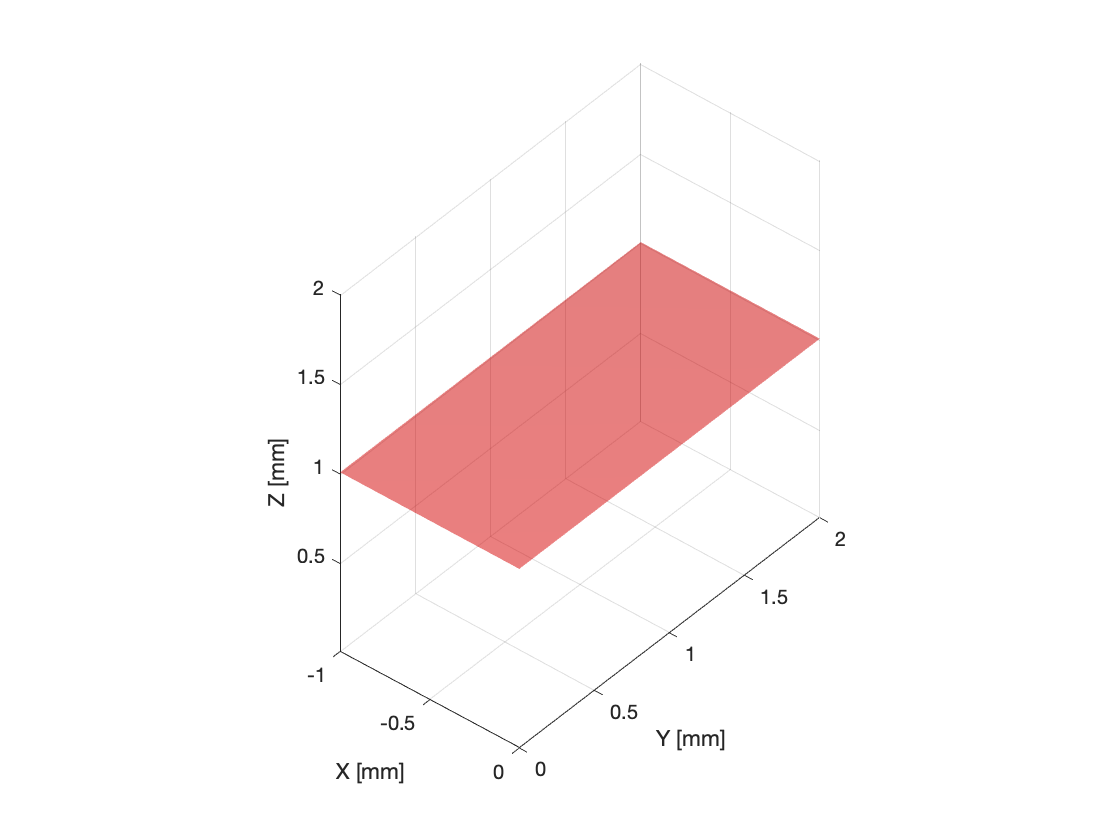

patch_Taula =   Patch with properties:

    FaceColor: [1 0 0]
    FaceAlpha: 0.5000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [1 2 3 4]
     Vertices: [4×3 double]

  Show all properties


% Vertex
v1 = [2 0 0.01];
v2 = [0 0 0.01];
v3 = [0 1 0.01];
v4 = [2 1 0.01];
v_taula = [v1 ; v2 ; v3; v4];

% Cares
f_taula = [1 2 3 4];

% Rotació inicial
rotacio_taulaX = 0;
rotacio_taulaY = 0;
rotacio_taulaZ = pi/2;

% Posicio inicial
trans_taula = transl(0,0,1);

% Ampliem Matriu
v_taula=[v_taula';ones(1,4)];

% Definim Matriu Transformació
T_taula = trans_taula * trotx(rotacio_taulaX) * troty(rotacio_taulaY) * trotz(rotacio_taulaZ);

% Apliquem la transformació
v_taula = T_taula*v_taula;

% Reduim Matriu
v_taula=v_taula(1:3,:)';

axis equal
hold on
view(40,40)
patch_Taula = FVsPlot(f_taula,v_taula,'red', 0.5)

### 3D model of a human body 

Situate the human model on the operating table

## Persona

Situem la persona en relació amb la taula.

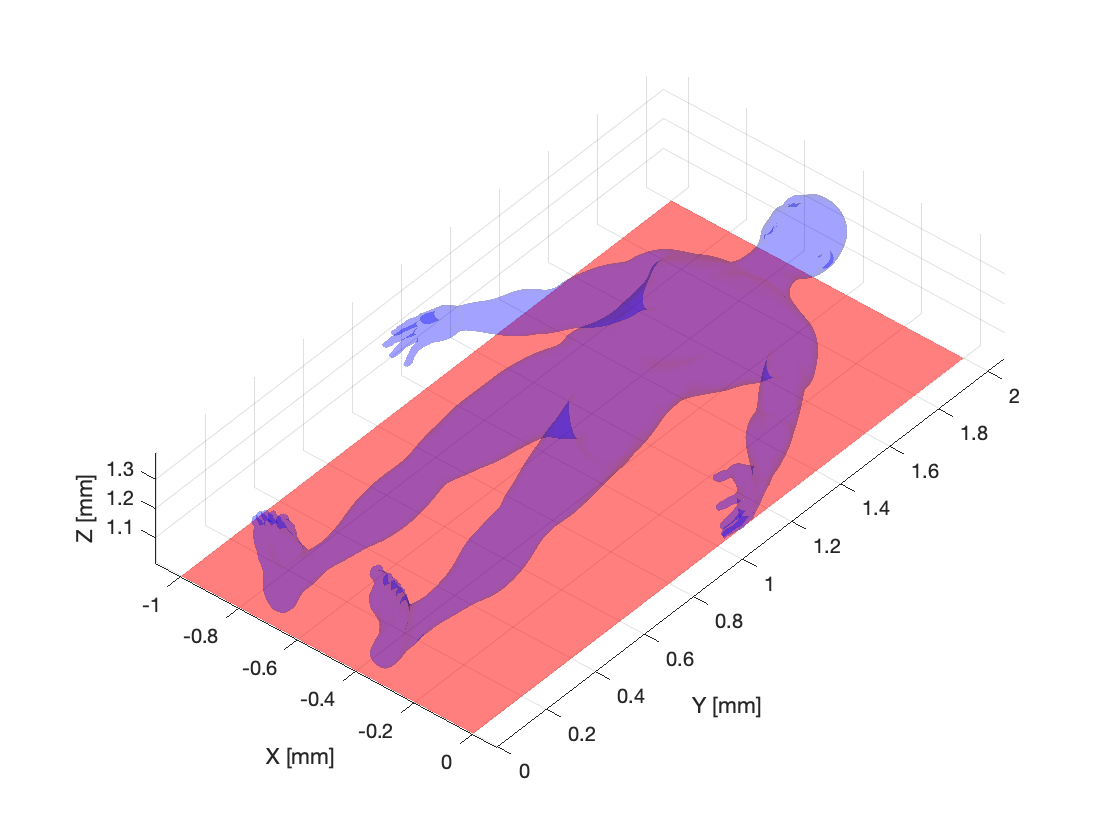

patch_Huma =   Patch with properties:

    FaceColor: [0 0 1]
    FaceAlpha: 0.2000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [48918×3 double]
     Vertices: [24461×3 double]

  Show all properties


% Vertex i Cares
load('F_V_Human_Body.mat')
f_huma = F;
v_huma = V;

% Rotació inicial
rotacio_humaZ = -pi/2;

% Escala
escala = 0.1;
v_huma = escala*v_huma;

% Posicio inicial
trans_huma = T_taula;

% Ampliem Matriu
v_huma=[v_huma';ones(1,length(v_huma))];

% Definim Matriu Transformació
T_huma = trans_huma * trotz(rotacio_humaZ) * transl(-0.5, 0, 0.2);

% Apliquem la transformació
v_huma = T_huma*v_huma;

% Reduim Matriu
v_huma = v_huma(1:3,:)';
patch_Huma = FVsPlot(f_huma,v_huma,'blue', 0.2)

### Human skull model

Situem el crani dins de la persona.

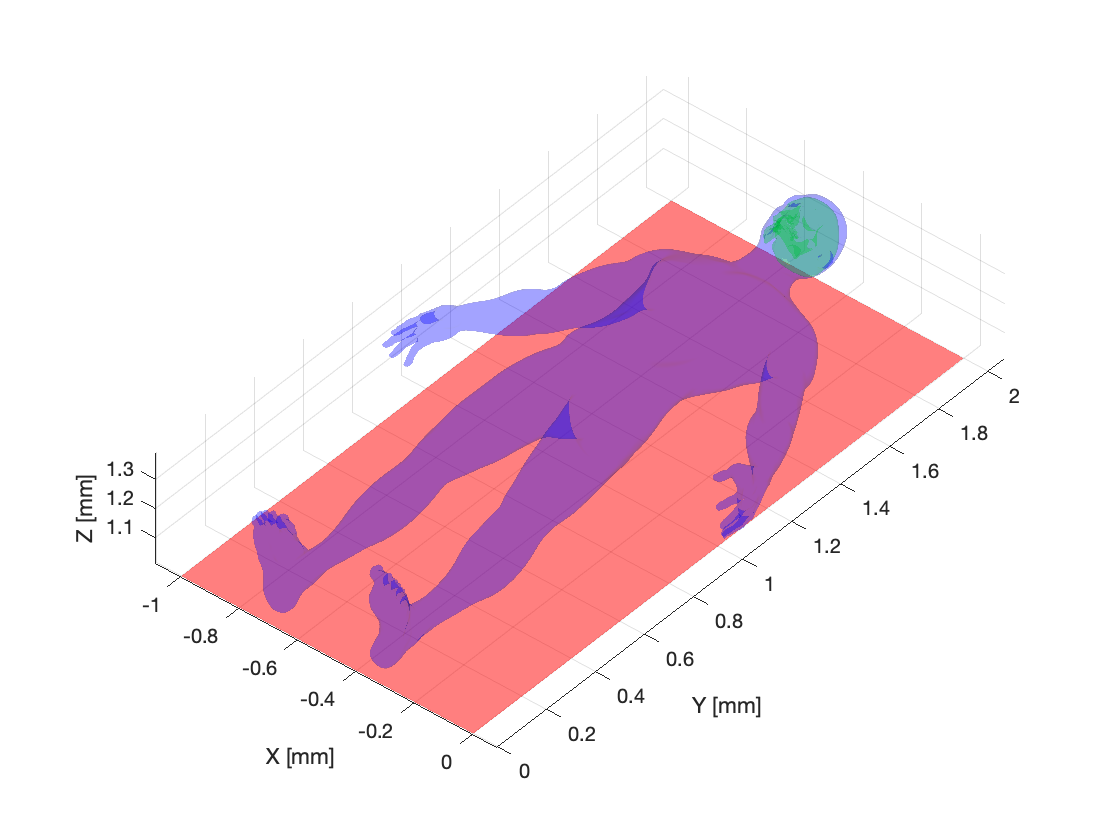

% Vertex i Cares
load('F_V_N_Skull.mat')
f_skull = Fa;
v_skull = Ve;

% Rotació inicial
rotacio_skullX = -1.48352646254480014;    % -85
rotacio_skullZ = -pi/2;

% Translació
t_skullX = 1.83;    % Puja baixa direccio columna vertebral
t_skullY = 0.5;
t_skullZ = 0.18;    % Puja baixa cap als ulls

% Escala
escala = 0.0077;
v_skull = escala*v_skull;

% Posicio inicial
trans_skull = T_taula;

% Ampliem Matriu
v_skull =[v_skull';ones(1,length(v_skull))];

% Definim Matriu Transformació
T_skull = trans_skull * transl(t_skullX,t_skullY,t_skullZ) * trotz(rotacio_skullZ) * trotx(rotacio_skullX);

% Apliquem la transformació
v_skull = T_skull*v_skull;

% Reduim Matriu
v_skull = v_skull(1:3,:)';

patch_Skull = FVsPlot(f_skull,v_skull,'green', 0.2);

### Dicom image vs Image reference frame

Go to ---- /MatlabDrive/Robotica_20_21_2Q/2_Rotations\3_Rotating_about_axis.mlx and use the Box as a container of the skull. You can infer the Image Reference Frame {I}

% Vertex
v = [0 0 0;1 0 0;1 1 0;0 1 0;0 0 1;1 0 1;1 1 1;0 1 1]

v =      0     0     0
     1     0     0
     1     1     0
     0     1     0
     0     0     1
     1     0     1
     1     1     1
     0     1     1


v_box = [0.215*v(:,1), 0.2*v(:,2),0.23*v(:,3)]

v_box =          0         0         0
    0.2150         0         0
    0.2150    0.2000         0
         0    0.2000         0
         0         0    0.2300
    0.2150         0    0.2300
    0.2150    0.2000    0.2300
         0    0.2000    0.2300


f_box = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8]

f_box =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8



% Rotació inicial


% Posicio inicial
trans_box = T_taula

trans_box =      0    -1     0     0
     1     0     0     0
     0     0     1     1
     0     0     0     1



% Ampliem Matriu
v_box = [v_box';ones(1,length(v_box))] 

v_box =          0    0.2150    0.2150         0         0    0.2150    0.2150         0
         0         0    0.2000    0.2000         0         0    0.2000    0.2000
         0         0         0         0    0.2300    0.2300    0.2300    0.2300
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



% Definim Matriu Transformació
T_box = trans_box * transl(1.85,0.40,0.07)

T_box =          0   -1.0000         0   -0.4000
    1.0000         0         0    1.8500
         0         0    1.0000    1.0700
         0         0         0    1.0000


T_image = T_box*trotx(pi/2)*trotz(pi)*troty(pi/2)*transl(-0.05,-0.25,0.05)

T_image =    -1.0000         0         0   -0.3500
         0         0   -1.0000    1.8000
         0   -1.0000         0    1.3200
         0         0         0    1.0000


% Apliquem la transformació
v_box = T_box*v_box

v_box =    -0.4000   -0.4000   -0.6000   -0.6000   -0.4000   -0.4000   -0.6000   -0.6000
    1.8500    2.0650    2.0650    1.8500    1.8500    2.0650    2.0650    1.8500
    1.0700    1.0700    1.0700    1.0700    1.3000    1.3000    1.3000    1.3000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



% Reduim Matriu
v_box=v_box(1:3,:)'

v_box =    -0.4000    1.8500    1.0700
   -0.4000    2.0650    1.0700
   -0.6000    2.0650    1.0700
   -0.6000    1.8500    1.0700
   -0.4000    1.8500    1.3000
   -0.4000    2.0650    1.3000
   -0.6000    2.0650    1.3000
   -0.6000    1.8500    1.3000


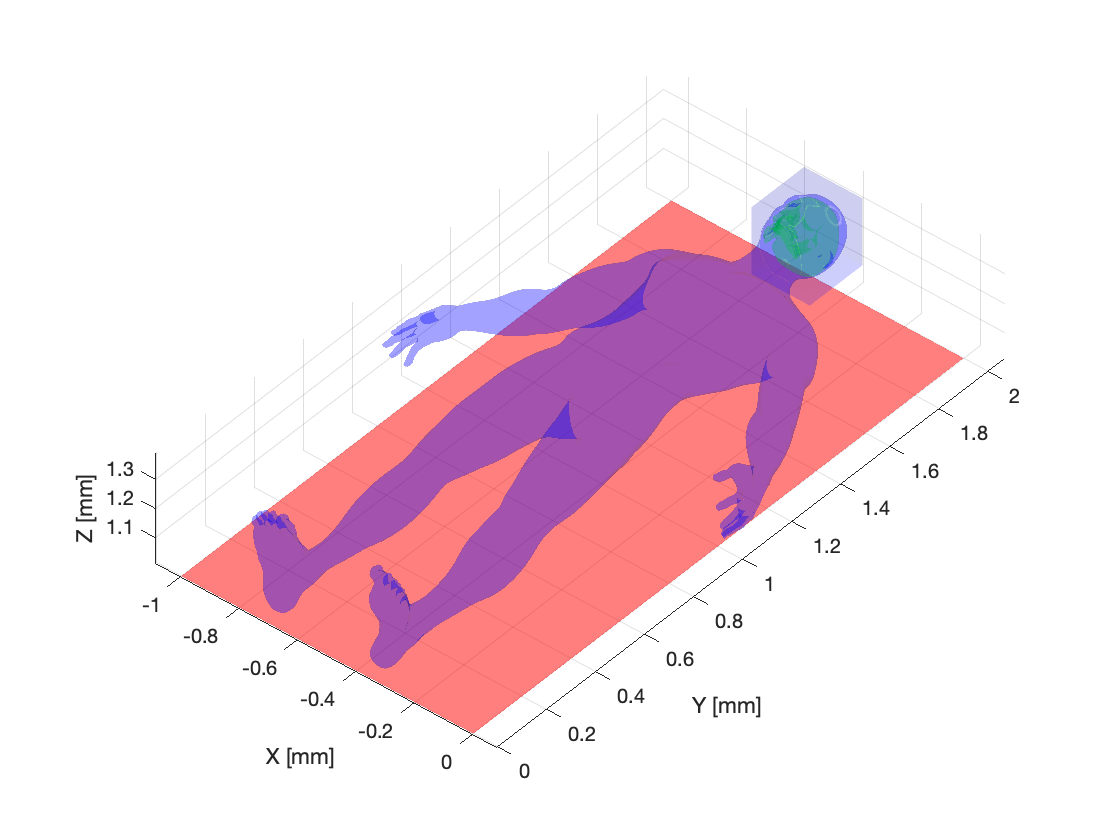

patch_Box =   Patch with properties:

    FaceColor: [0 0 1]
    FaceAlpha: 0.1000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [6×4 double]
     Vertices: [8×3 double]

  Show all properties



axis equal
hold on
view(40,40)
patch_Box = FVsPlot(f_box,v_box,'blue', 0.1)

### Fiducials

Use the Dicom images to register the fiducial relative to Image Reference Frame {I}.

Think about how many reference frames are envolved.

%% put your code Here 
fiducial_32 = T_image*transl(0.076,0.2,-0.05-32*0.0014)

fiducial_32 =    -1.0000         0         0   -0.4260
         0         0   -1.0000    1.8948
         0   -1.0000         0    1.1200
         0         0         0    1.0000


fiducial_65 = T_image*transl(0.205,0.2,-0.05-65*0.0014)

fiducial_65 =    -1.0000         0         0   -0.5550
         0         0   -1.0000    1.9410
         0   -1.0000         0    1.1200
         0         0         0    1.0000


fiducial_94 = T_image*transl(0.132,0.044,-0.05-94*0.0014)

fiducial_94 =    -1.0000         0         0   -0.4820
         0         0   -1.0000    1.9816
         0   -1.0000         0    1.2760
         0         0         0    1.0000


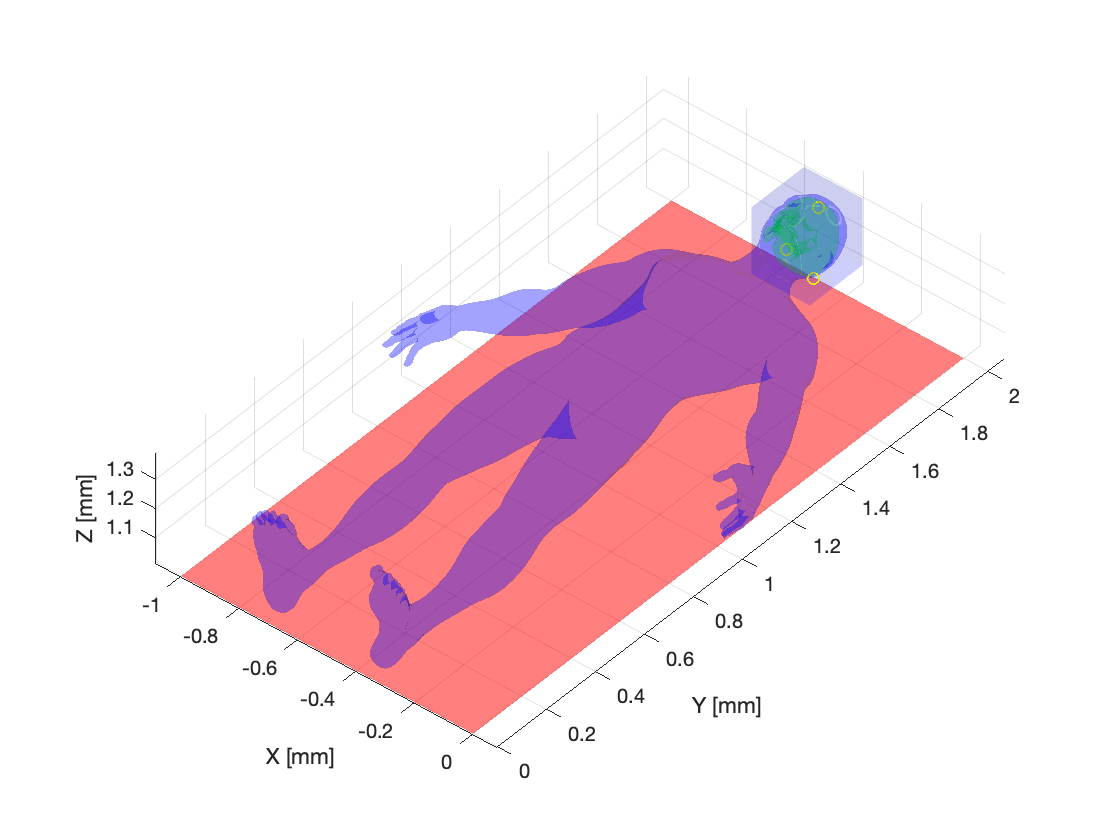


scatter3(fiducial_32(1,4),fiducial_32(2,4),fiducial_32(3,4),'yellow','LineWidth',1)
scatter3(fiducial_65(1,4),fiducial_65(2,4),fiducial_65(3,4),'yellow','LineWidth',1)
scatter3(fiducial_94(1,4),fiducial_94(2,4),fiducial_94(3,4),'yellow','LineWidth',1)

### Tumor points

Use the Dicom images to get the points of the outer perimeter of the tumor relative to Image Reference Frame {I}.

%% put your code Here
[tumor_X, tumor_Y, tumor_Z] = sphere()

tumor_X =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.1564   -0.1488   -0.1266   -0.0919   -0.0483    0.0000    0.0483    0.0919    0.1266    0.1488    0.1564    0.1488    0.1266    0.0919    0.0483    0.0000   -0.0483   -0.0919   -0.1266   -0.1488   -0.1564
   -0.3090   -0.2939   -0.2500   -0.1816   -0.0955    0.0000    0.0955    0.1816    0.2500    0.2939    0.3090    0.2939    0.2500    0.1816    0.0955    0.0000   -0.0955   -0.1816   -0.2500   -0.2939   -0.3090
   -0.4540   -0.4318   -0.3673   -0.2668   -0.1403    0.0000    0.1403    0.2668    0.3673    0.4318    0.4540    0.4318    0.3673    0.2668    0.1403    0.0000   -0.1403   -0.2668   -0.3673   -0.4318   -0.4540
   -0.5878   -0.5590   -0.4755   -0.3455   -0.1816    0.0000    0.1816    0.3455    0.4755    0.5590    0.5878    0.5590    0.4755    0.3455    0.

tumor_Y =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.0483   -0.0919   -0.1266   -0.1488   -0.1564   -0.1488   -0.1266   -0.0919   -0.0483         0    0.0483    0.0919    0.1266    0.1488    0.1564    0.1488    0.1266    0.0919    0.0483         0
         0   -0.0955   -0.1816   -0.2500   -0.2939   -0.3090   -0.2939   -0.2500   -0.1816   -0.0955         0    0.0955    0.1816    0.2500    0.2939    0.3090    0.2939    0.2500    0.1816    0.0955         0
         0   -0.1403   -0.2668   -0.3673   -0.4318   -0.4540   -0.4318   -0.3673   -0.2668   -0.1403         0    0.1403    0.2668    0.3673    0.4318    0.4540    0.4318    0.3673    0.2668    0.1403         0
         0   -0.1816   -0.3455   -0.4755   -0.5590   -0.5878   -0.5590   -0.4755   -0.3455   -0.1816         0    0.1816    0.3455    0.4755    0.

tumor_Z =    -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877
   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511
   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910
   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.

fvc = surf2patch(tumor_X,tumor_Y,tumor_Z,'triangles')

fvc = struct with fields:
       faces: [800×3 double]
    vertices: [441×3 double]


v_tumor = [fvc.vertices';ones(1,length(fvc.vertices))]

v_tumor =          0   -0.1564   -0.3090   -0.4540   -0.5878   -0.7071   -0.8090   -0.8910   -0.9511   -0.9877   -1.0000   -0.9877   -0.9511   -0.8910   -0.8090   -0.7071   -0.5878   -0.4540   -0.3090   -0.1564         0         0   -0.1488   -0.2939   -0.4318   -0.5590   -0.6725   -0.7694   -0.8474   -0.9045   -0.9393   -0.9511   -0.9393   -0.9045   -0.8474   -0.7694   -0.6725   -0.5590   -0.4318   -0.2939   -0.1488         0         0   -0.1266   -0.2500   -0.3673   -0.4755   -0.5721   -0.6545   -0.7208
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0483   -0.0955   -0.1403   -0.1816   -0.2185   -0.2500   -0.2753   -0.2939   -0.3052   -0.3090   -0.3052   -0.2939   -0.2753   -0.2500   -0.2185   -0.1816   -0.1403   -0.0955   -0.0483         0         0   -0.0919   -0.1816   -0.2668   -0.3455   -0.4156   -0.475

% Apliquem la transformació
T_tumor = T_image*transl(0.138,0.094,-0.05-78*0.0014)

T_tumor =    -1.0000         0         0   -0.4880
         0         0   -1.0000    1.9592
         0   -1.0000         0    1.2260
         0         0         0    1.0000


v_tumor = T_image*transl(0.138,0.094,-0.05-78*0.0014)*trscale(0.04)*v_tumor

v_tumor =    -0.4880   -0.4817   -0.4756   -0.4698   -0.4645   -0.4597   -0.4556   -0.4524   -0.4500   -0.4485   -0.4480   -0.4485   -0.4500   -0.4524   -0.4556   -0.4597   -0.4645   -0.4698   -0.4756   -0.4817   -0.4880   -0.4880   -0.4820   -0.4762   -0.4707   -0.4656   -0.4611   -0.4572   -0.4541   -0.4518   -0.4504   -0.4500   -0.4504   -0.4518   -0.4541   -0.4572   -0.4611   -0.4656   -0.4707   -0.4762   -0.4820   -0.4880   -0.4880   -0.4829   -0.4780   -0.4733   -0.4690   -0.4651   -0.4618   -0.4592
    1.9992    1.9987    1.9972    1.9948    1.9916    1.9875    1.9827    1.9774    1.9716    1.9655    1.9592    1.9529    1.9468    1.9410    1.9357    1.9309    1.9268    1.9236    1.9212    1.9197    1.9192    1.9992    1.9987    1.9972    1.9948    1.9916    1.9875    1.9827    1.9774    1.9716    1.9655    1.9592    1.9529    1.9468    1.9410    1.9357    1.9309    1.9268    1.9236    1.9212    1.9197    1.9192    1.9992    1.9987    1.9972    1.9948    1.9916    1.9875    1.982


% Reduim Matriu
v_tumor=v_tumor(1:3,:)'

v_tumor =    -0.4880    1.9992    1.2260
   -0.4817    1.9987    1.2260
   -0.4756    1.9972    1.2260
   -0.4698    1.9948    1.2260
   -0.4645    1.9916    1.2260
   -0.4597    1.9875    1.2260
   -0.4556    1.9827    1.2260
   -0.4524    1.9774    1.2260
   -0.4500    1.9716    1.2260
   -0.4485    1.9655    1.2260


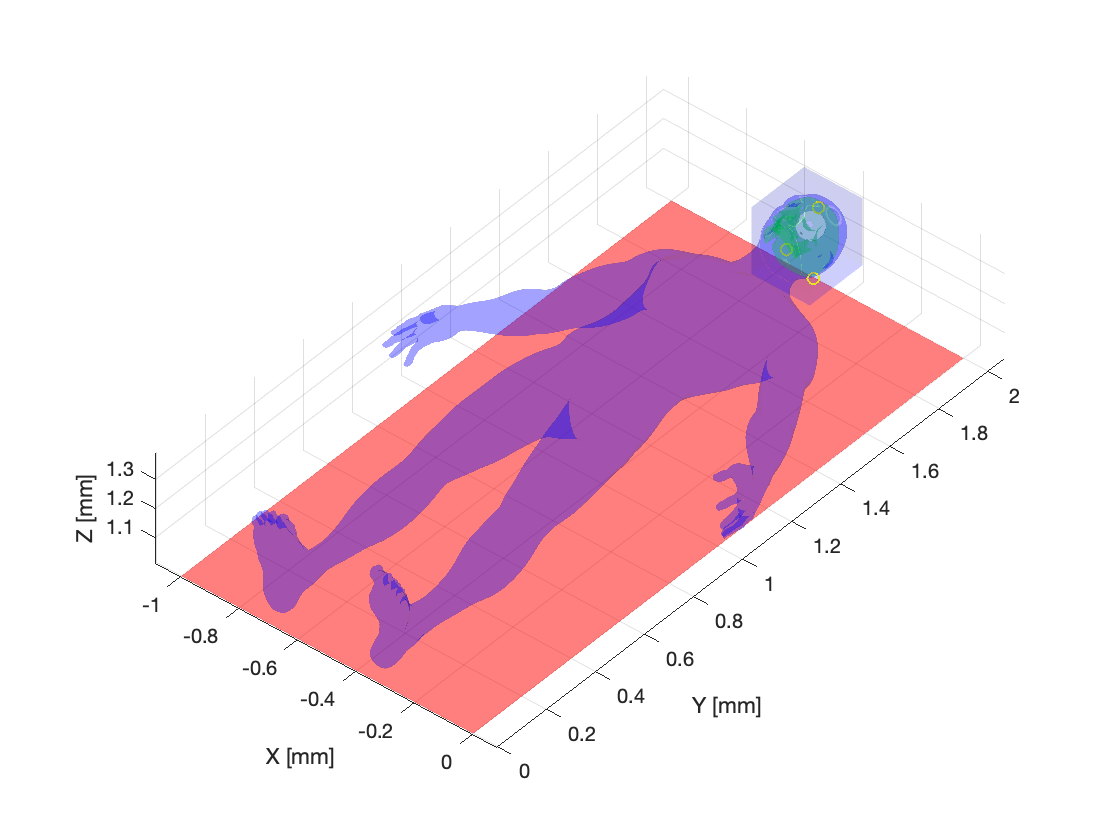

patch_Tumor =   Patch with properties:

    FaceColor: [1 1 1]
    FaceAlpha: 0.8000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [800×3 double]
     Vertices: [441×3 double]

  Show all properties



% Dades interessants
max_min_tumor(1,1) = max(v_tumor(:,1)); % max x
max_min_tumor(2,1) = min(v_tumor(:,1)); % min x

max_min_tumor(1,2) = max(v_tumor(:,2)); % max y
max_min_tumor(2,2) = min(v_tumor(:,2)); % min y

max_min_tumor(1,3) = max(v_tumor(:,3)); % max z
max_min_tumor(2,3) = min(v_tumor(:,3)); % min z

centre_Tumor = [(max_min_tumor(1,1)+max_min_tumor(2,1))/2,(max_min_tumor(1,2)+max_min_tumor(2,2))/2,(max_min_tumor(1,3)+max_min_tumor(2,3))/2];

radi = (max_min_tumor(1,3)-max_min_tumor(2,3))/4; % max en z - min en z, diametro tumor


patch_Tumor = FVsPlot(fvc.faces,v_tumor,'white', 0.8)

## *First approach (10%)  *

*Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

### Robot manipulator

Consider  the best position of manipulator to be nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

Use: p560.base & p560.tool to locate the Puma and add the tool.

mdl_puma560
p560.base = T_taula*transl(2.4,0.7,0.15)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, fastRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (-0.7, 2.4, 1.15), RPY/xyz = (90, 0, 0) deg         
 


% Marquem limits per a centrar la camara en el que interessa
% el cap
axis equal
xlim([-1 0])
ylim([1 4])
zlim([1 2.5])

vista_persp = [-210, 30];
workSpace = [-1 0 2 3 1 5];
p560.plot(qr,'zoom',2.5,'workspace', workSpace,'view',vista_persp );

Eliminem el crani i la caixa

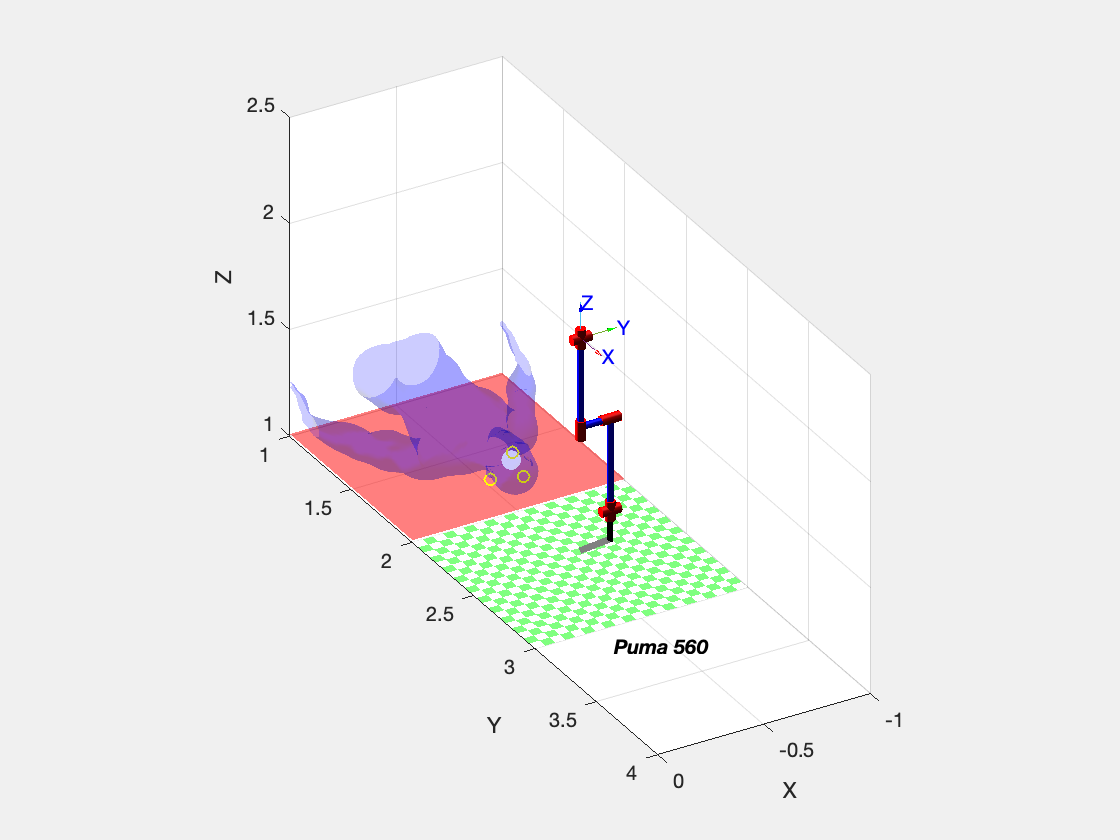

delete(patch_Skull);
delete(patch_Box);

### Reference Frames

Display all necessary reference frame. Use best scale to see it.

- {U} Univers [0 0 0]

- {R} Robot

- {I} Image

- {Tb} Table_body

- {Tt} Table tool

- {EE} End Efector

T_univers = transl(0,0,0)

T_univers =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


%T_robot = T_taula*transl(2.7,0.5,0.15)*trotz(-3*pi/2)
T_robot = T_taula*transl(2.4,0.7,0.15)*trotz(-3*pi/2)

T_robot =    -1.0000         0         0   -0.7000
         0   -1.0000         0    2.4000
         0         0    1.0000    1.1500
         0         0         0    1.0000


%trplot(T_image, 'frame', 'R', 'color', 'black')
%trplot(T_univers, 'frame', 'R', 'color', 'b')
%trplot(T_taula, 'frame', 'R', 'color', 'red')
%trplot(T_box, 'frame', 'R', 'color', 'green')
%trplot(T_robot, 'frame', 'R', 'color', 'yellow')

### Transformations

Get all transformation

%% put your code Here 
T_image_robot = inv(T_image)*T_robot

T_image_robot =     1.0000         0         0    0.3500
         0         0   -1.0000    0.1700
         0    1.0000         0   -0.6000
         0         0         0    1.0000


### Tumor points in Robot Frame.

v_tumorX = [v_tumor';ones(1,length(v_tumor))];
v_tumor_robot = T_image_robot*v_tumorX;
v_tumor_robot=v_tumor_robot(1:3,:)';

% Aixo no funciona be, no se exactament que es el que hauria de fer
%FVsPlot(fvc.faces,v_tumor_robot,'black', 0.7);

## Surgery (40%)

### Biospy

Prepare a script that perform a biopsy. Zoom in the scene and record a video with thwe best view.

Hem de fer:

- Anar a buscar l'eina

- Situar-nos a la part superior del cap

- Entrar a pel tumor

- Sortir

% Dividim moviment en 3
p560.tool = SE3(0,0,0.17);
t = [0:0.05:1]';

## Biopsia

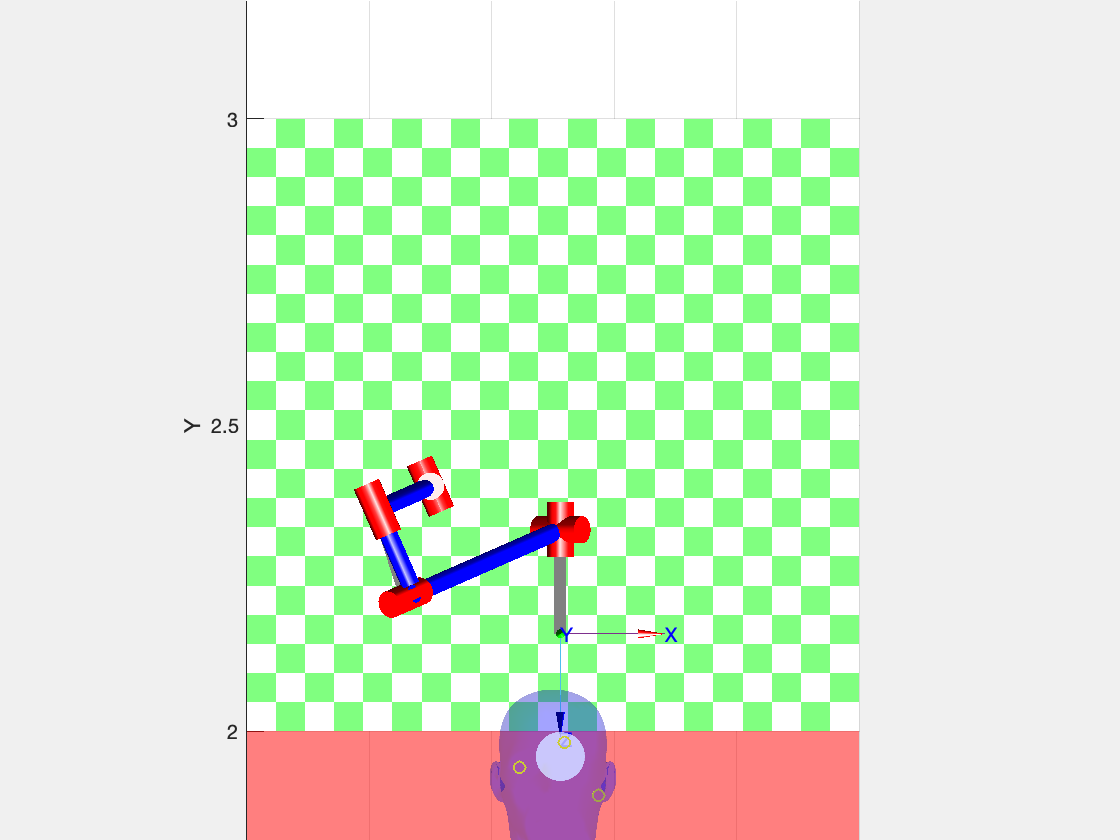

T_Eina = SE3(T_robot(1,4),T_robot(2,4)+0.5,T_robot(3,4))*SE3.Ry(pi);
T_Ini = SE3(T_tumor(1,4),T_tumor(2,4)+0.2,T_tumor(3,4))*SE3.Rx(pi/2);
T3_Dins = SE3(T_tumor(1,4),T_tumor(2,4),T_tumor(3,4))*SE3.Rx(pi/2);


% 1. Anem a buscar a l'eina
q_Eina = p560.ikine6s(T_Eina, 't');
q_Ini = p560.ikine6s(T_Ini);
q = mtraj(@tpoly, q_Eina, q_Ini, t);
p560.plot(q,'view',vista_persp)  

% 2. Entrem al tumor
q = ctraj(T_Ini, T3_Dins, t);
q = p560.ikine6s(q,'r');
p560.plot(q,'top')

% 3. Sortim del tumor
q = ctraj(T3_Dins, T_Ini, t);
q = p560.ikine6s(q,'r');
p560.plot(q,'top')  

### Trepanation

Prepare a script that perform trepanation.

Hem de fer:

- Agafar eina

- Anar a la part superior del cap

- Fem Forat (1r desplaçem una mica al costat, 2n fem forat cercle)

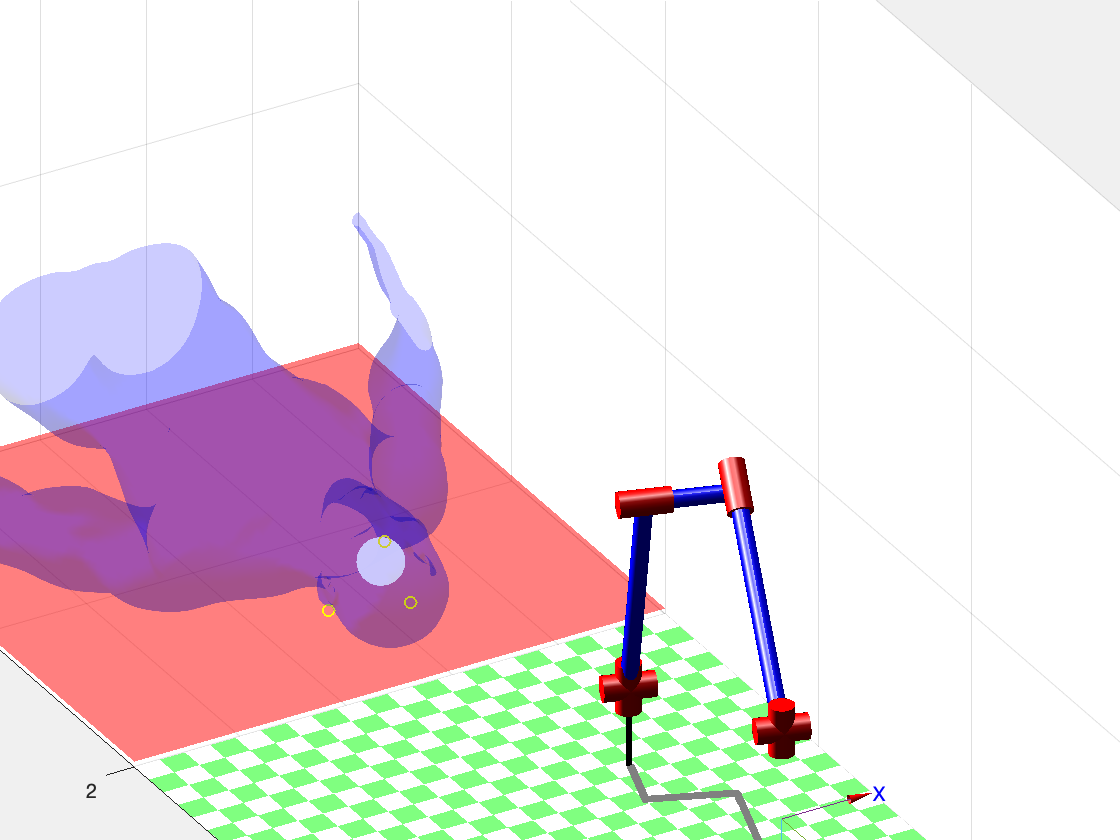

% 0. Anem a buscar l'eina
T_Eina;
T_Ini;
q_Eina;
q_Ini;
q = mtraj(@tpoly, q_Ini, q_Eina, t);
p560.plot(q, 'view', vista_persp)  

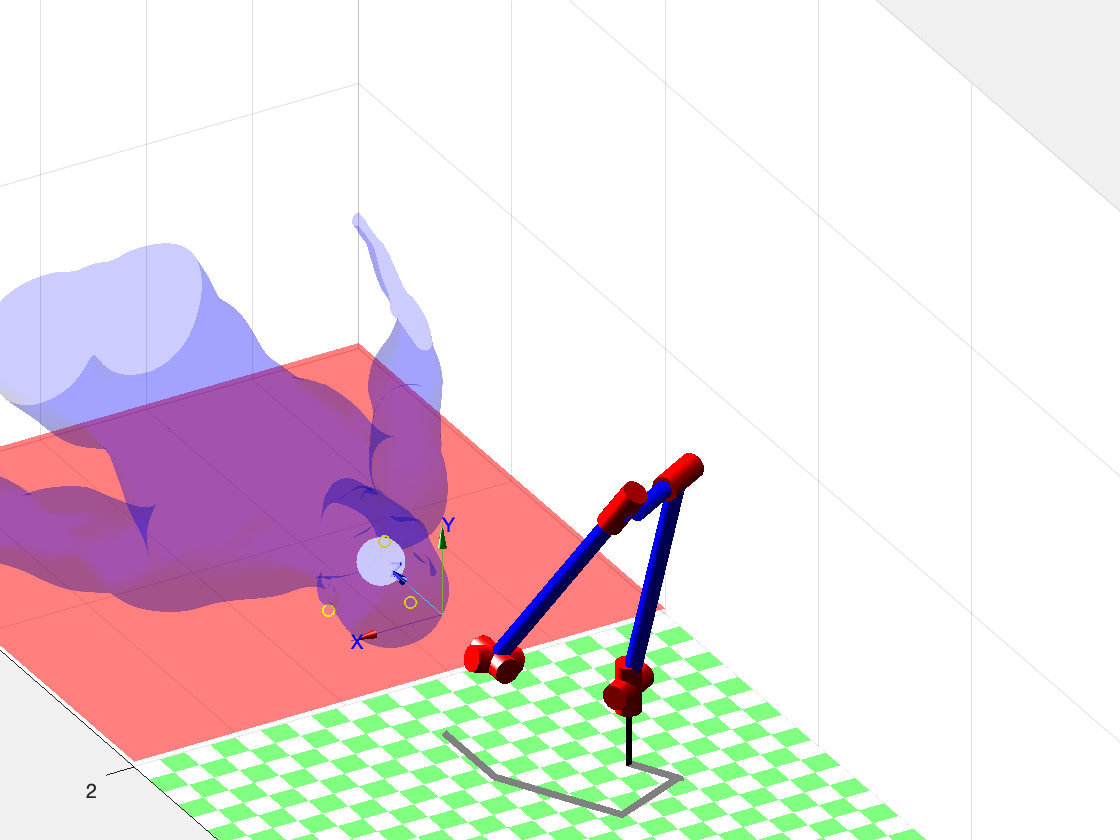

% 1. Anem a la posicio inicial
q = mtraj(@tpoly, q_Eina, q_Ini, t);
p560.plot(q, 'view', vista_persp)  

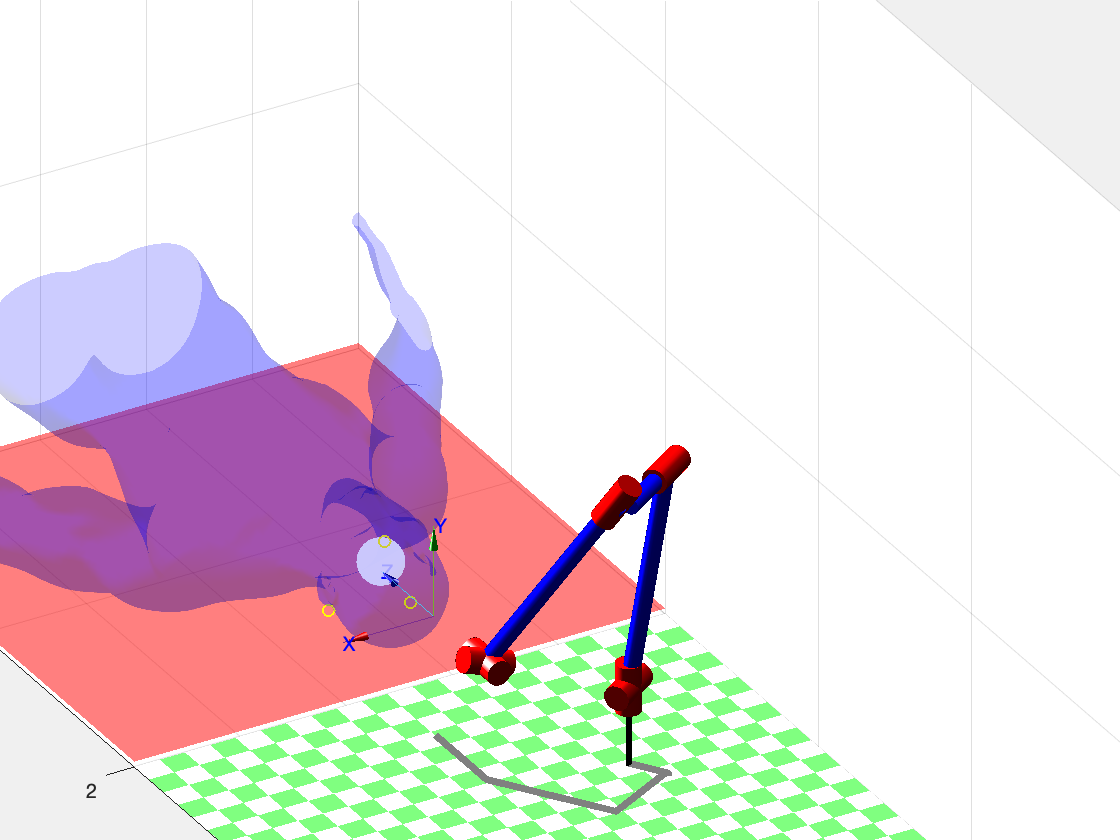

% 2. Anem a buscar el forat

% Distancia desde l'agulla fins a tocar el cap
offset_cap = 0.09;

% Calculem el perimetre a tallar
T_Centre = T_Ini*SE3(0,0,offset_cap);

radi_Trepanacio = radi*0.8;   % radi o radi/2?
n = 100;

for i=1:n
    Laser_Pose(:,:,i)= T_Centre*SE3.Rz(2*pi*i/n)*SE3(radi_Trepanacio, 0,0)*SE3.Rx(pi/4);
end


% Apuntem al inici del forat
p_ini = Laser_Pose(:,:,1);
T = SE3(p_ini.t(1), p_ini.t(2), p_ini.t(3)) * SE3.Rx(pi/2);
T3_Gir = T * SE3(0,0,-offset_cap);
q_Gir = ctraj(T_Ini, T3_Gir, t);
q_Gir = p560.ikine6s(q_Gir);
p560.plot(q_Gir, 'view', vista_persp);

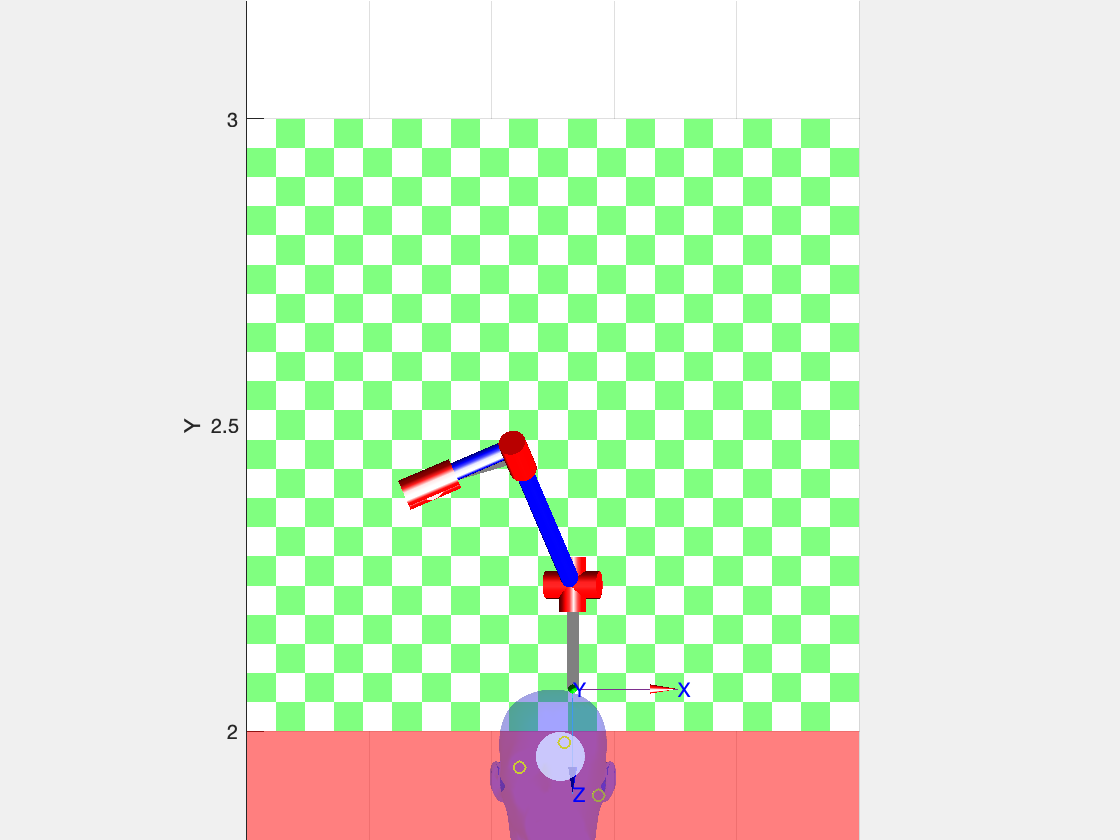

% 3. Eina a sobre del cap - Anem a T4_Cap
T4_Cap = T_Centre*SE3(radi,0,0);
q_Tornar = ctraj(T3_Gir, T4_Cap, t);
q_Tornar = p560.ikine6s(q_Tornar, 'b');
p560.plot(q_Tornar, 'top');

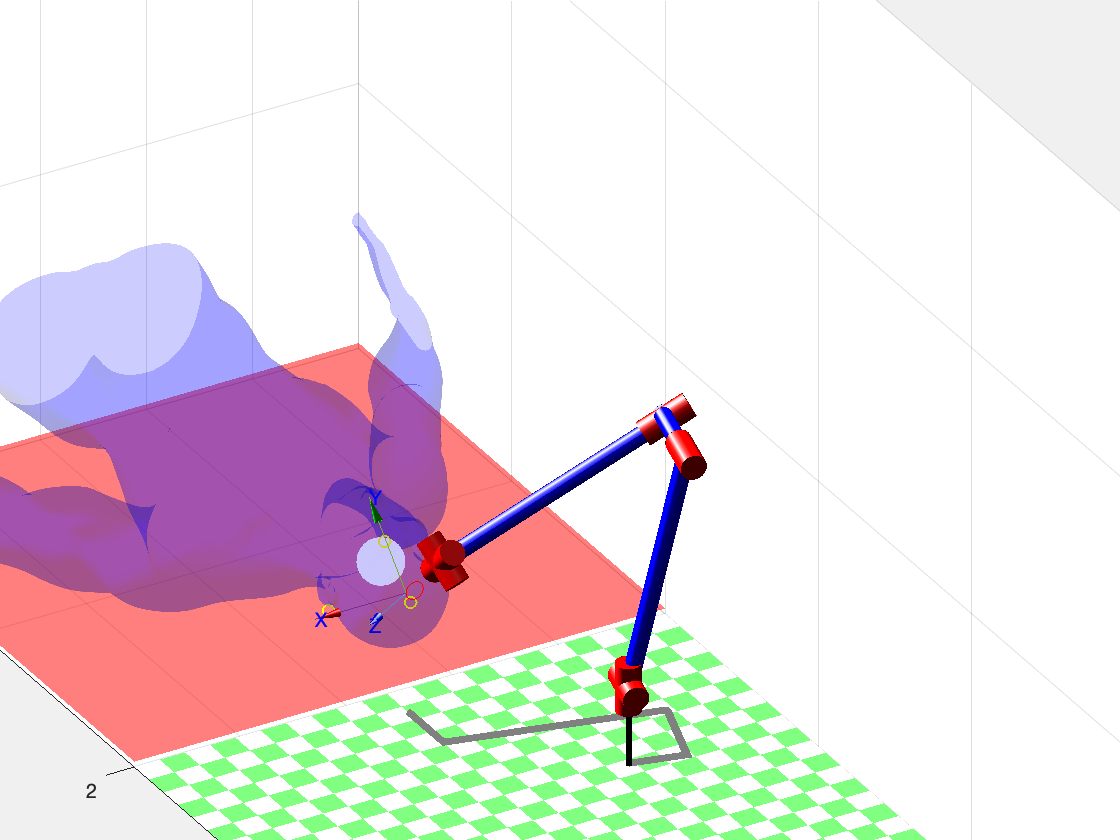

% 4. Tallem (Cercle) 
% Mostrem la part a tallar
plotCircle3D([T_Centre.t(1),T_Centre.t(2),T_Centre.t(3)],[0,1,0],radi_Trepanacio);
% Trepanem 
q = p560.ikine6s(Laser_Pose, 'run'); 
p560.plot(q, 'view', vista_persp)

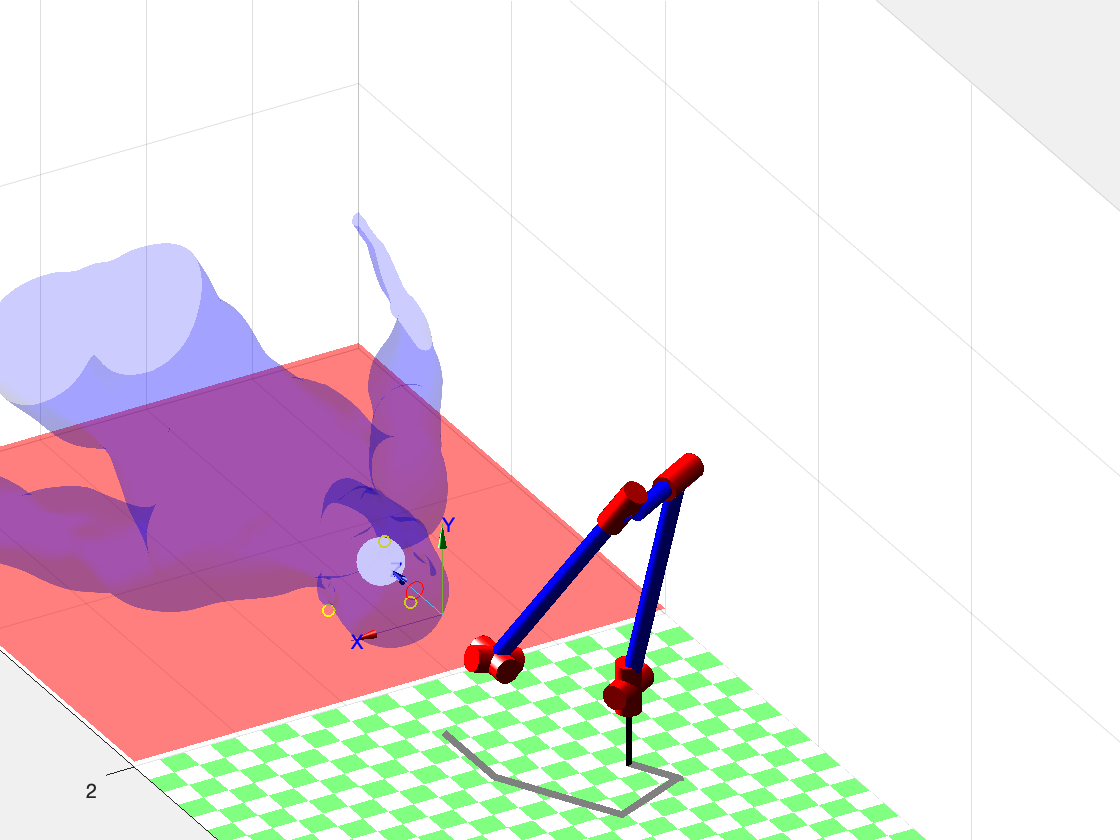

% 5. Tornem a la posicio inicial
q = ctraj(Laser_Pose(:,:,n), T_Ini, t);
q = p560.ikine6s(q);
p560.plot(q, 'view', vista_persp);

### Tumor burning

Prepare a script that perform tumor burning with the laser.

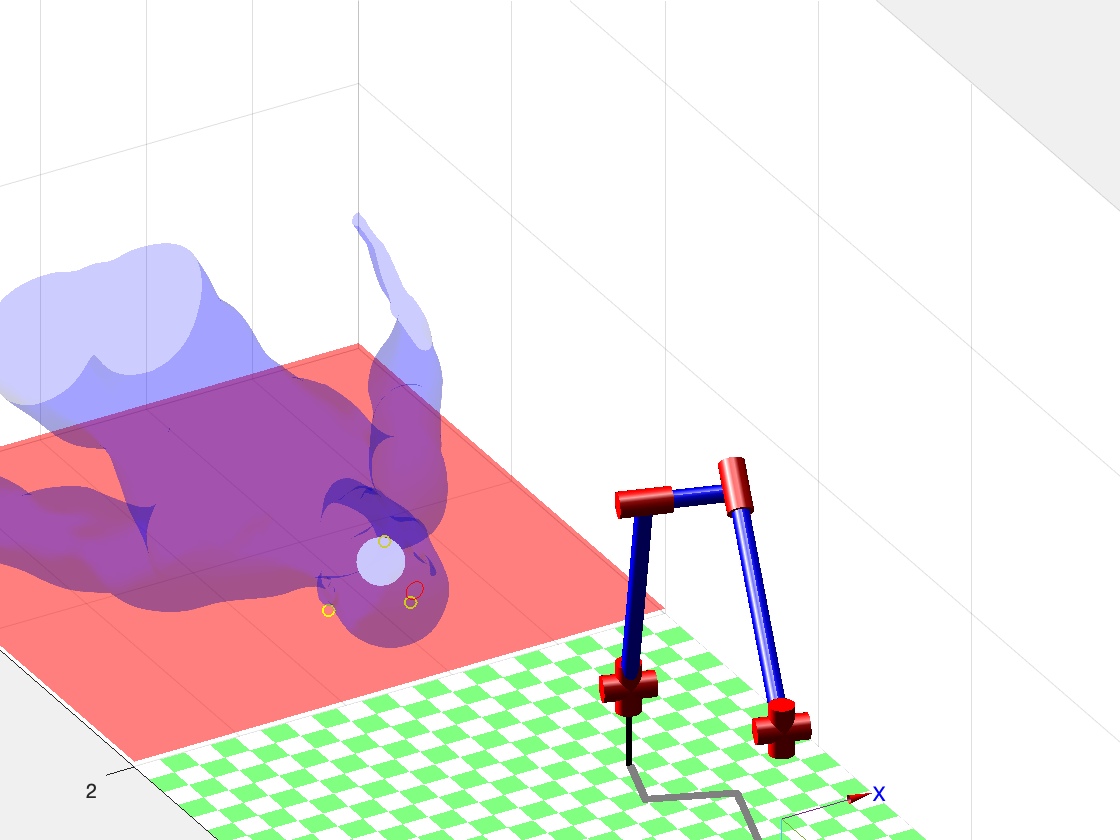

% 0. Anem a buscar l'eina
T_Eina;
T_Ini;
q_Eina;
q_Ini;
q = mtraj(@tpoly, q_Ini, q_Eina, t);
p560.plot(q, 'view', vista_persp)  

% 1. Anem a la posicio inicial
q = mtraj(@tpoly, q_Eina, q_Ini, t);
p560.plot(q, 'view', vista_persp)   

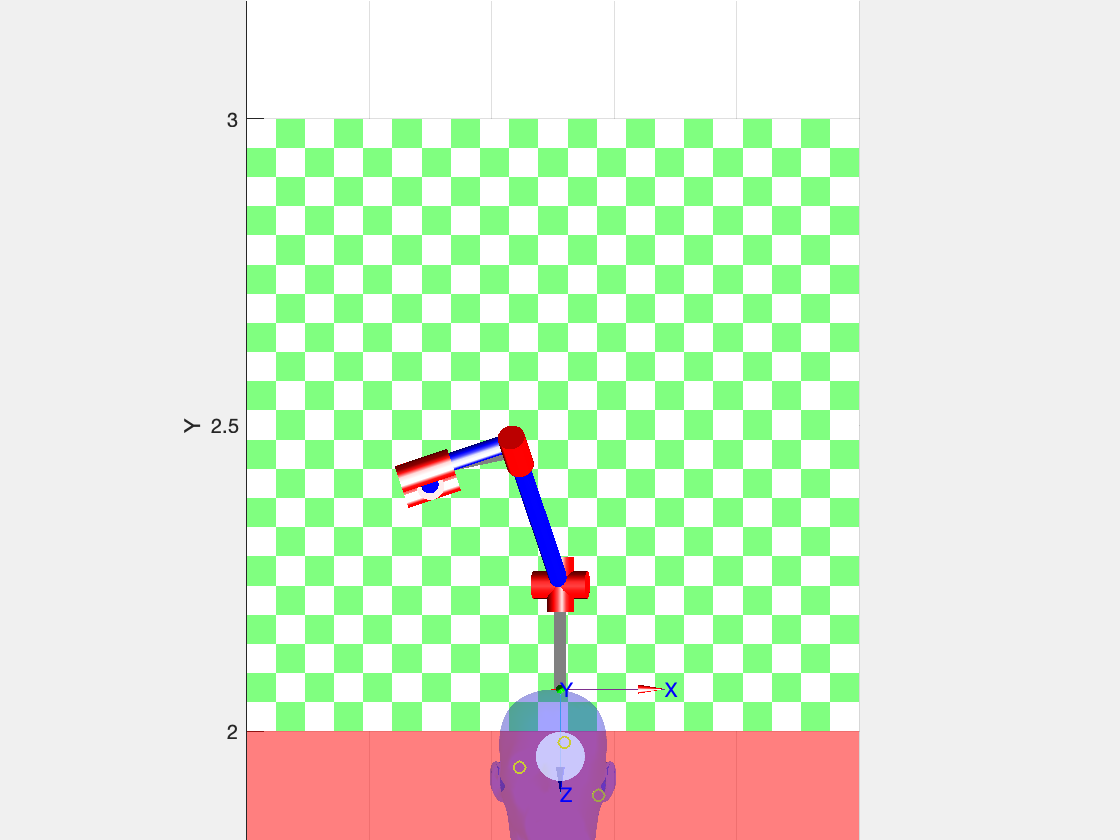

% 2. Eina a sobre del cap
T_Centre;
q = ctraj(T_Ini, T_Centre, t);
q = p560.ikine6s(q, 'b');
p560.plot(q, 'top');

% 3: Entrem a cremar el tumor
% L'idea es cremar desde 4 angles diferents. Cremarem abaix, esquerra,
% dreta i abaix del tumor.
% Cada 4 iteracions anirem disminuint el angle d'incidencia
max_min_tumor; % 2-min
    
% Repetim 3 cops els 4 angles
for rad=1:3
    %Cremem en 4 direccions. Abaix, Esquerra, Dreta i Adalt.
    for i=1:4
        %Ens encarem amb el angle que toca 
        if i == 1
            T1 = T_Centre*SE3.Rx(pi/(10*rad));
        end
        if i == 2
            T1 = T_Centre*SE3.Ry(pi/(10*rad));
        end
        if i == 3
            T1 = T_Centre*SE3.Rx(-pi/(10*rad));
        end
        if i == 4
            T1 = T_Centre*SE3.Ry(-pi/(10*rad)); 
        end
        q = ctraj(T_Centre, T1, 20);
        q = p560.ikine6s(q);
        p560.plot(q, 'view', vista_persp);
        
        %Entrem al cap rectes
        T2 = T1*SE3(0,0,T_Centre.t(2)-centre_Tumor(2)); % Anem a parar al centre del Tumor (en profunditat)
        q = ctraj(T1, T2, 20);
        q = p560.ikine6s(q);
        p560.plot(q, 'view', vista_persp);
        
        %Sortim del cap
        q = ctraj(T2, T1, 20);
        q = p560.ikine6s(q);
        p560.plot(q, 'view', vista_persp);
        
        %Tornem a la posicio inicial
        q = ctraj(T1, T_Centre, 20);
        q = p560.ikine6s(q);
        p560.plot(q, 'view', vista_persp);
    end
end

%Tornem a la posicio inicial
q = ctraj(T_Centre, T_Ini, t);
q = p560.ikine6s(q);
p560.plot(q, 'view', vista_persp);

% load('Cone.mat')
% f_cone = fvc.faces;
% v_cone = [fvc.vertices';ones(1,length(fvc.vertices))];
% v_cone = trscale(0.1)*T_tumor*v_cone
% v_cone = v_cone(1:3,:)';
% axis equal
% hold on
% view(40,40)
% FVsPlot(f_cone,v_cone,'red')

## *Second approach: ( 40%)*

Modify your code  to repeat the exercise if  the table with the patient is given as happend in the Rosa video.

To know the head relative pose with respect to the Puma Robot ...

*See:  **‘4_Sckeching_Key_ideas_students.mlx’ and ‘5_Skull_pose estimation.mlx’ for inspiration.*

It is desirable to have a pdf report with the following items:

1.- Biopsy trajectory. Plot the profiles of the trajectory and the velocity vector in End Effector Reference Frame

2.- Trepanation. Plot the manipulability index during all time trepanation is been performed. Plot the velocities ellipsoide when the manipulability is lower.

3.- How long it takes the ablation of all the tumor.

%open('3_Second_approach_Patient_pose.fig')

use  'patch'  functions to model it.

clear all
clf

## Taula

Col·loquem una taula on s'estirarà la persona.

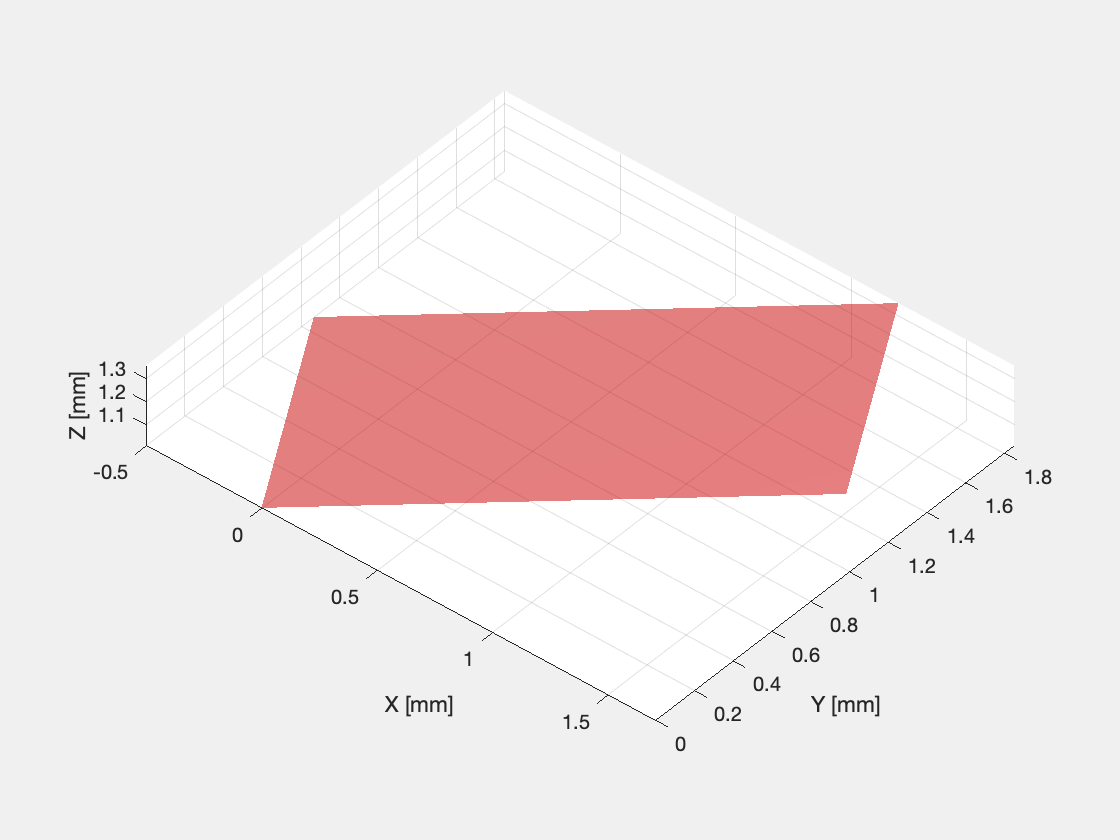

patch_Taula =   Patch with properties:

    FaceColor: [1 0 0]
    FaceAlpha: 0.5000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [1 2 3 4]
     Vertices: [4×3 double]

  Show all properties


% Vertex
v1 = [2 0 0.01];
v2 = [0 0 0.01];
v3 = [0 1 0.01];
v4 = [2 1 0.01];
v_taula = [v1 ; v2 ; v3; v4];

% Cares
f_taula = [1 2 3 4];

% Rotació inicial
rotacio_taulaX = 0;
rotacio_taulaY = -pi/18;
rotacio_taulaZ = pi/6;

    
% Posicio inicial
trans_taula = transl(0,0,1);

% Ampliem Matriu
v_taula=[v_taula';ones(1,4)];

% Definim Matriu Transformació
T_taula = trans_taula * trotx(rotacio_taulaX)* trotz(rotacio_taulaZ) * troty(rotacio_taulaY) ;

% Apliquem la transformació
v_taula = T_taula*v_taula;

% Reduim Matriu
v_taula=v_taula(1:3,:)';

axis equal
hold on
view(40,40)
patch_Taula = FVsPlot(f_taula,v_taula,'red', 0.5)

### 3D model of a human body 

Situate the human model on the operating table

## Persona

Situem la persona en relació amb la taula.

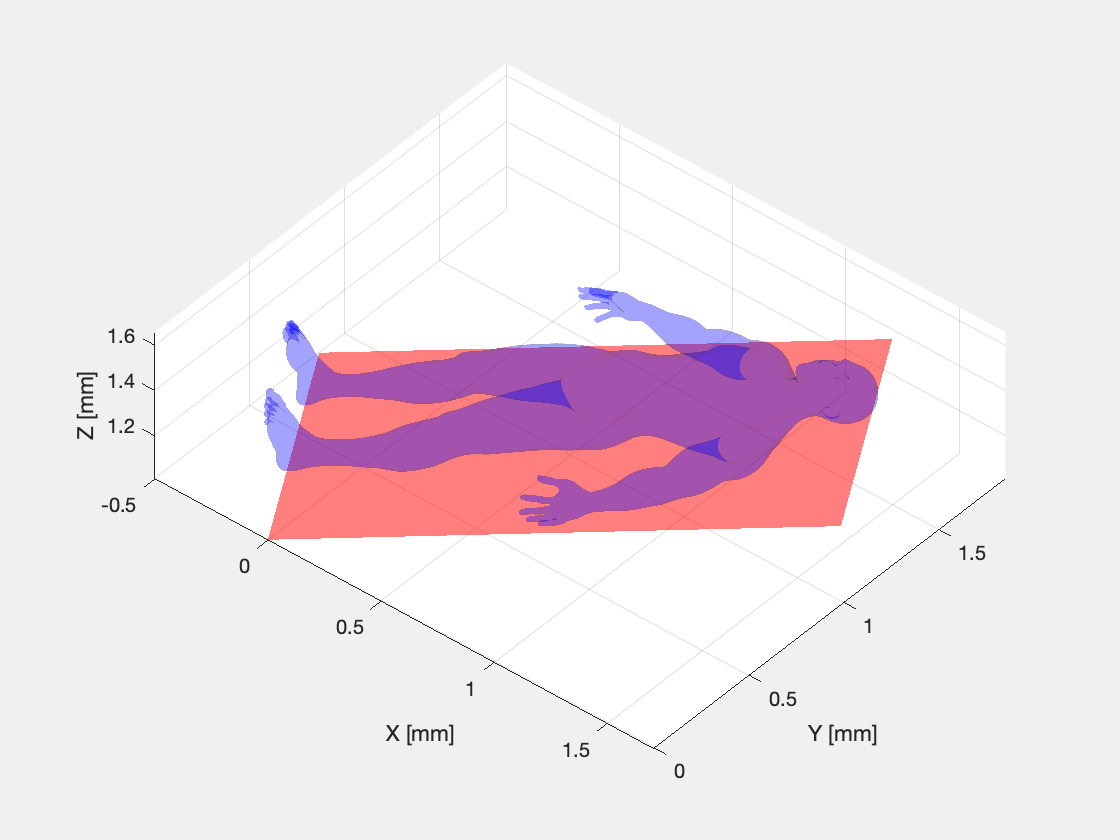

patch_Huma =   Patch with properties:

    FaceColor: [0 0 1]
    FaceAlpha: 0.2000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [48918×3 double]
     Vertices: [24461×3 double]

  Show all properties


% Vertex i Cares
load('F_V_Human_Body.mat')
f_huma = F;
v_huma = V;

% Rotació inicial
rotacio_humaZ = -pi/2;

% Escala
escala = 0.1;
v_huma = escala*v_huma;

% Posicio inicial
trans_huma = T_taula;

% Ampliem Matriu
v_huma=[v_huma';ones(1,length(v_huma))];

% Definim Matriu Transformació
T_huma = trans_huma * trotz(rotacio_humaZ) * transl(-0.5, 0, 0.2);

% Apliquem la transformació
v_huma = T_huma*v_huma;

% Reduim Matriu
v_huma = v_huma(1:3,:)';
patch_Huma = FVsPlot(f_huma,v_huma,'blue', 0.2)

### Human skull model

Situem el crani dins de la persona.

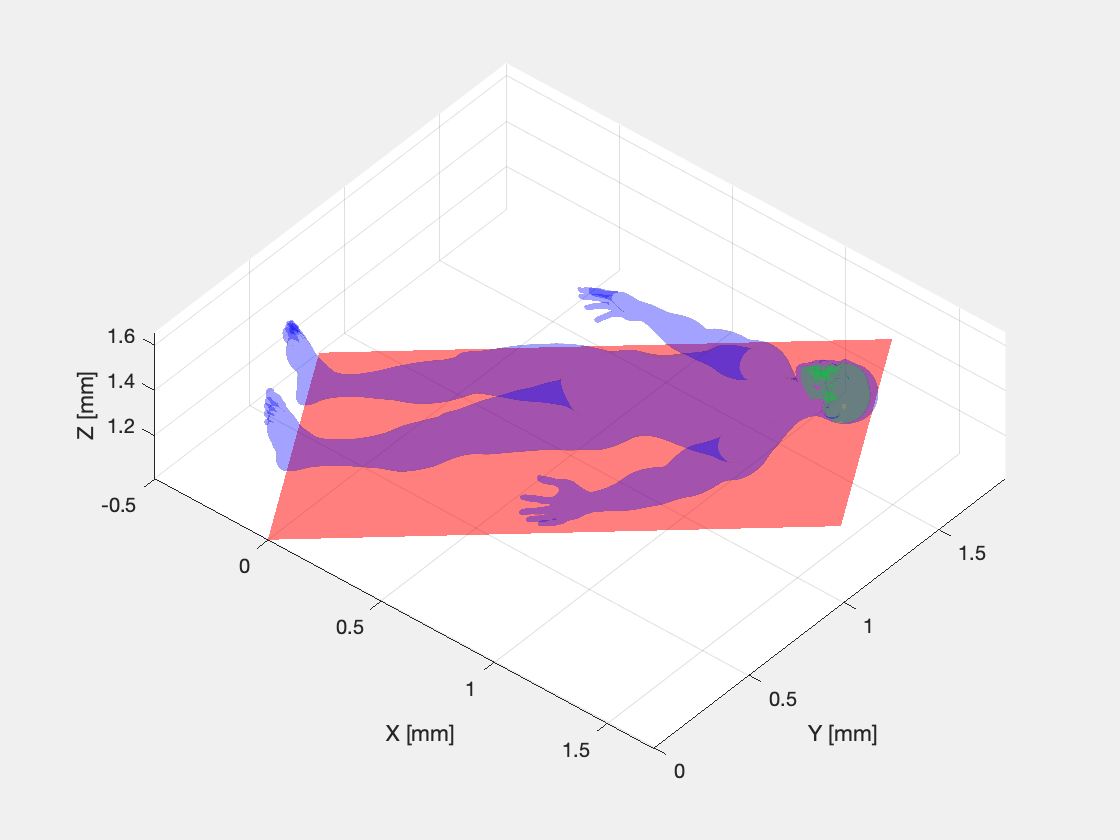

% Vertex i Cares
load('F_V_N_Skull.mat')
f_skull = Fa;
v_skull = Ve;

% Rotació inicial
rotacio_skullX = -1.48352646254480014;    % -85
rotacio_skullZ = -pi/2;

% Translació
t_skullX = 1.83;    % Puja baixa direccio columna vertebral
t_skullY = 0.5;
t_skullZ = 0.18;    % Puja baixa cap als ulls

% Escala
escala = 0.0077;
v_skull = escala*v_skull;

% Posicio inicial
trans_skull = T_taula;

% Ampliem Matriu
v_skull =[v_skull';ones(1,length(v_skull))];

% Definim Matriu Transformació
T_skull = trans_skull * transl(t_skullX,t_skullY,t_skullZ) * trotz(rotacio_skullZ) * trotx(rotacio_skullX);

% Apliquem la transformació
v_skull = T_skull*v_skull;

% Reduim Matriu
v_skull = v_skull(1:3,:)';

patch_Skull = FVsPlot(f_skull,v_skull,'green', 0.2);

### Dicom image vs Image reference frame

Go to ---- /MatlabDrive/Robotica_20_21_2Q/2_Rotations\3_Rotating_about_axis.mlx and use the Box as a container of the skull. You can infer the Image Reference Frame {I}

% Vertex
v = [0 0 0;1 0 0;1 1 0;0 1 0;0 0 1;1 0 1;1 1 1;0 1 1]

v =      0     0     0
     1     0     0
     1     1     0
     0     1     0
     0     0     1
     1     0     1
     1     1     1
     0     1     1


v_box = [0.215*v(:,1), 0.2*v(:,2),0.23*v(:,3)]

v_box =          0         0         0
    0.2150         0         0
    0.2150    0.2000         0
         0    0.2000         0
         0         0    0.2300
    0.2150         0    0.2300
    0.2150    0.2000    0.2300
         0    0.2000    0.2300


f_box = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8]

f_box =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8



% Rotació inicial


% Posicio inicial
trans_box = T_taula

trans_box =     0.8529   -0.5000   -0.1504         0
    0.4924    0.8660   -0.0868         0
    0.1736         0    0.9848    1.0000
         0         0         0    1.0000



% Ampliem Matriu
v_box = [v_box';ones(1,length(v_box))] 

v_box =          0    0.2150    0.2150         0         0    0.2150    0.2150         0
         0         0    0.2000    0.2000         0         0    0.2000    0.2000
         0         0         0         0    0.2300    0.2300    0.2300    0.2300
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



% Definim Matriu Transformació
T_box = trans_box * transl(1.85,0.40,0.07)

T_box =     0.8529   -0.5000   -0.1504    1.3673
    0.4924    0.8660   -0.0868    1.2513
    0.1736         0    0.9848    1.3902
         0         0         0    1.0000


T_image = T_box*trotx(pi/2)*trotz(pi)*troty(pi/2)*transl(-0.05,-0.25,0.05)

T_image =    -0.5000    0.1504   -0.8529    1.3120
    0.8660    0.0868   -0.4924    1.1617
         0   -0.9848   -0.1736    1.6277
         0         0         0    1.0000


% Apliquem la transformació
v_box = T_box*v_box

v_box =     1.3673    1.5506    1.4506    1.2673    1.3327    1.5161    1.4161    1.2327
    1.2513    1.3571    1.5304    1.4245    1.2313    1.3372    1.5104    1.4045
    1.3902    1.4275    1.4275    1.3902    1.6167    1.6540    1.6540    1.6167
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



% Reduim Matriu
v_box=v_box(1:3,:)'

v_box =     1.3673    1.2513    1.3902
    1.5506    1.3571    1.4275
    1.4506    1.5304    1.4275
    1.2673    1.4245    1.3902
    1.3327    1.2313    1.6167
    1.5161    1.3372    1.6540
    1.4161    1.5104    1.6540
    1.2327    1.4045    1.6167


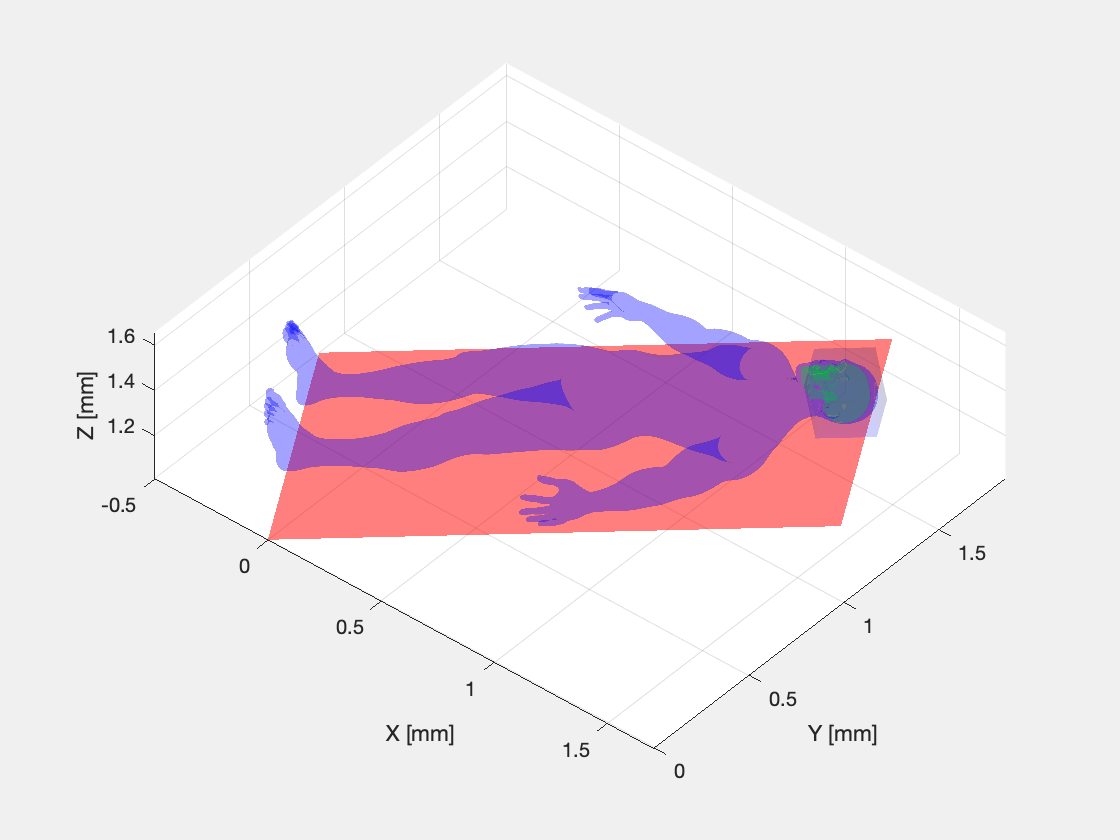

patch_Box =   Patch with properties:

    FaceColor: [0 0 1]
    FaceAlpha: 0.1000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [6×4 double]
     Vertices: [8×3 double]

  Show all properties



axis equal
hold on
view(40,40)
patch_Box = FVsPlot(f_box,v_box,'blue', 0.1)

### Fiducials

Use the Dicom images to register the fiducial relative to Image Reference Frame {I}.

Think about how many reference frames are envolved.

%% put your code Here 
fiducial_32 = T_image*transl(0.076,0.2,-0.05-32*0.0014)

fiducial_32 =    -0.5000    0.1504   -0.8529    1.3850
    0.8660    0.0868   -0.4924    1.2915
         0   -0.9848   -0.1736    1.4472
         0         0         0    1.0000


fiducial_65 = T_image*transl(0.205,0.2,-0.05-65*0.0014)

fiducial_65 =    -0.5000    0.1504   -0.8529    1.3599
    0.8660    0.0868   -0.4924    1.4260
         0   -0.9848   -0.1736    1.4552
         0         0         0    1.0000


fiducial_94 = T_image*transl(0.132,0.044,-0.05-94*0.0014)

fiducial_94 =    -0.5000    0.1504   -0.8529    1.4075
    0.8660    0.0868   -0.4924    1.3692
         0   -0.9848   -0.1736    1.6159
         0         0         0    1.0000


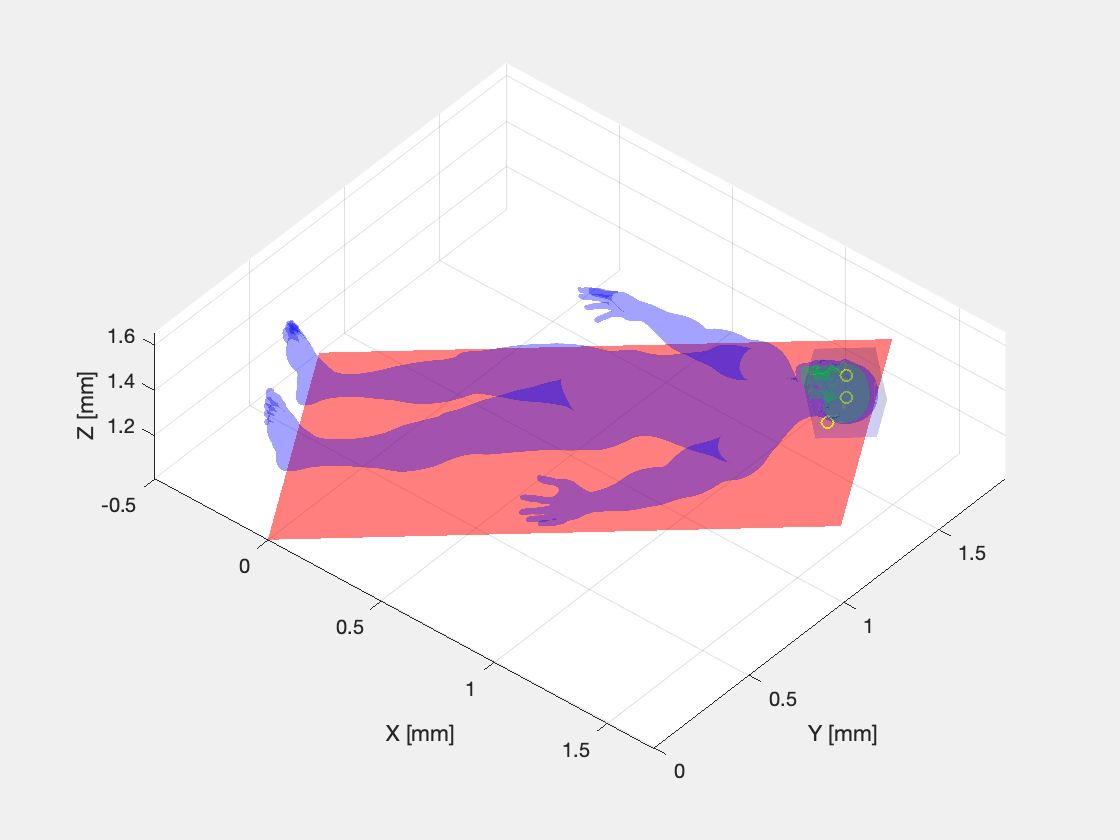



scatter3(fiducial_32(1,4),fiducial_32(2,4),fiducial_32(3,4),'yellow','LineWidth',1)
scatter3(fiducial_65(1,4),fiducial_65(2,4),fiducial_65(3,4),'yellow','LineWidth',1)
scatter3(fiducial_94(1,4),fiducial_94(2,4),fiducial_94(3,4),'yellow','LineWidth',1)

### Tumor points

Use the Dicom images to get the points of the outer perimeter of the tumor relative to Image Reference Frame {I}.

%% put your code Here
[tumor_X, tumor_Y, tumor_Z] = sphere()

tumor_X =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.1564   -0.1488   -0.1266   -0.0919   -0.0483    0.0000    0.0483    0.0919    0.1266    0.1488    0.1564    0.1488    0.1266    0.0919    0.0483    0.0000   -0.0483   -0.0919   -0.1266   -0.1488   -0.1564
   -0.3090   -0.2939   -0.2500   -0.1816   -0.0955    0.0000    0.0955    0.1816    0.2500    0.2939    0.3090    0.2939    0.2500    0.1816    0.0955    0.0000   -0.0955   -0.1816   -0.2500   -0.2939   -0.3090
   -0.4540   -0.4318   -0.3673   -0.2668   -0.1403    0.0000    0.1403    0.2668    0.3673    0.4318    0.4540    0.4318    0.3673    0.2668    0.1403    0.0000   -0.1403   -0.2668   -0.3673   -0.4318   -0.4540
   -0.5878   -0.5590   -0.4755   -0.3455   -0.1816    0.0000    0.1816    0.3455    0.4755    0.5590    0.5878    0.5590    0.4755    0.3455    0.

tumor_Y =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.0483   -0.0919   -0.1266   -0.1488   -0.1564   -0.1488   -0.1266   -0.0919   -0.0483         0    0.0483    0.0919    0.1266    0.1488    0.1564    0.1488    0.1266    0.0919    0.0483         0
         0   -0.0955   -0.1816   -0.2500   -0.2939   -0.3090   -0.2939   -0.2500   -0.1816   -0.0955         0    0.0955    0.1816    0.2500    0.2939    0.3090    0.2939    0.2500    0.1816    0.0955         0
         0   -0.1403   -0.2668   -0.3673   -0.4318   -0.4540   -0.4318   -0.3673   -0.2668   -0.1403         0    0.1403    0.2668    0.3673    0.4318    0.4540    0.4318    0.3673    0.2668    0.1403         0
         0   -0.1816   -0.3455   -0.4755   -0.5590   -0.5878   -0.5590   -0.4755   -0.3455   -0.1816         0    0.1816    0.3455    0.4755    0.

tumor_Z =    -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877   -0.9877
   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511   -0.9511
   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910   -0.8910
   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.8090   -0.

fvc = surf2patch(tumor_X,tumor_Y,tumor_Z,'triangles')

fvc = struct with fields:
       faces: [800×3 double]
    vertices: [441×3 double]


v_tumor = [fvc.vertices';ones(1,length(fvc.vertices))]

v_tumor =          0   -0.1564   -0.3090   -0.4540   -0.5878   -0.7071   -0.8090   -0.8910   -0.9511   -0.9877   -1.0000   -0.9877   -0.9511   -0.8910   -0.8090   -0.7071   -0.5878   -0.4540   -0.3090   -0.1564         0         0   -0.1488   -0.2939   -0.4318   -0.5590   -0.6725   -0.7694   -0.8474   -0.9045   -0.9393   -0.9511   -0.9393   -0.9045   -0.8474   -0.7694   -0.6725   -0.5590   -0.4318   -0.2939   -0.1488         0         0   -0.1266   -0.2500   -0.3673   -0.4755   -0.5721   -0.6545   -0.7208
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0483   -0.0955   -0.1403   -0.1816   -0.2185   -0.2500   -0.2753   -0.2939   -0.3052   -0.3090   -0.3052   -0.2939   -0.2753   -0.2500   -0.2185   -0.1816   -0.1403   -0.0955   -0.0483         0         0   -0.0919   -0.1816   -0.2668   -0.3455   -0.4156   -0.475

% Apliquem la transformació
T_tumor = T_image*transl(0.138,0.094,-0.05-78*0.0014)

T_tumor =    -0.5000    0.1504   -0.8529    1.3930
    0.8660    0.0868   -0.4924    1.3677
         0   -0.9848   -0.1736    1.5628
         0         0         0    1.0000


v_tumor = T_image*transl(0.138,0.094,-0.05-78*0.0014)*trscale(0.04)*v_tumor

v_tumor =     1.4271    1.4298    1.4316    1.4324    1.4323    1.4312    1.4292    1.4263    1.4225    1.4180    1.4130    1.4074    1.4014    1.3953    1.3891    1.3830    1.3771    1.3716    1.3667    1.3624    1.3588    1.4271    1.4293    1.4307    1.4311    1.4306    1.4292    1.4269    1.4237    1.4198    1.4152    1.4101    1.4046    1.3987    1.3928    1.3868    1.3810    1.3754    1.3703    1.3658    1.3619    1.3588    1.4271    1.4286    1.4293    1.4291    1.4280    1.4260    1.4232    1.4197
    1.3874    1.3818    1.3757    1.3695    1.3633    1.3571    1.3513    1.3458    1.3409    1.3366    1.3331    1.3304    1.3287    1.3279    1.3281    1.3293    1.3314    1.3344    1.3383    1.3428    1.3480    1.3874    1.3818    1.3759    1.3698    1.3637    1.3576    1.3518    1.3463    1.3414    1.3372    1.3337    1.3310    1.3293    1.3285    1.3286    1.3297    1.3318    1.3347    1.3385    1.3429    1.3480    1.3874    1.3825    1.3772    1.3716    1.3660    1.3604    1.355


% Reduim Matriu
v_tumor=v_tumor(1:3,:)'

v_tumor =     1.4271    1.3874    1.5697
    1.4298    1.3818    1.5696
    1.4316    1.3757    1.5694
    1.4324    1.3695    1.5690
    1.4323    1.3633    1.5684
    1.4312    1.3571    1.5677
    1.4292    1.3513    1.5669
    1.4263    1.3458    1.5659
    1.4225    1.3409    1.5649
    1.4180    1.3366    1.5639


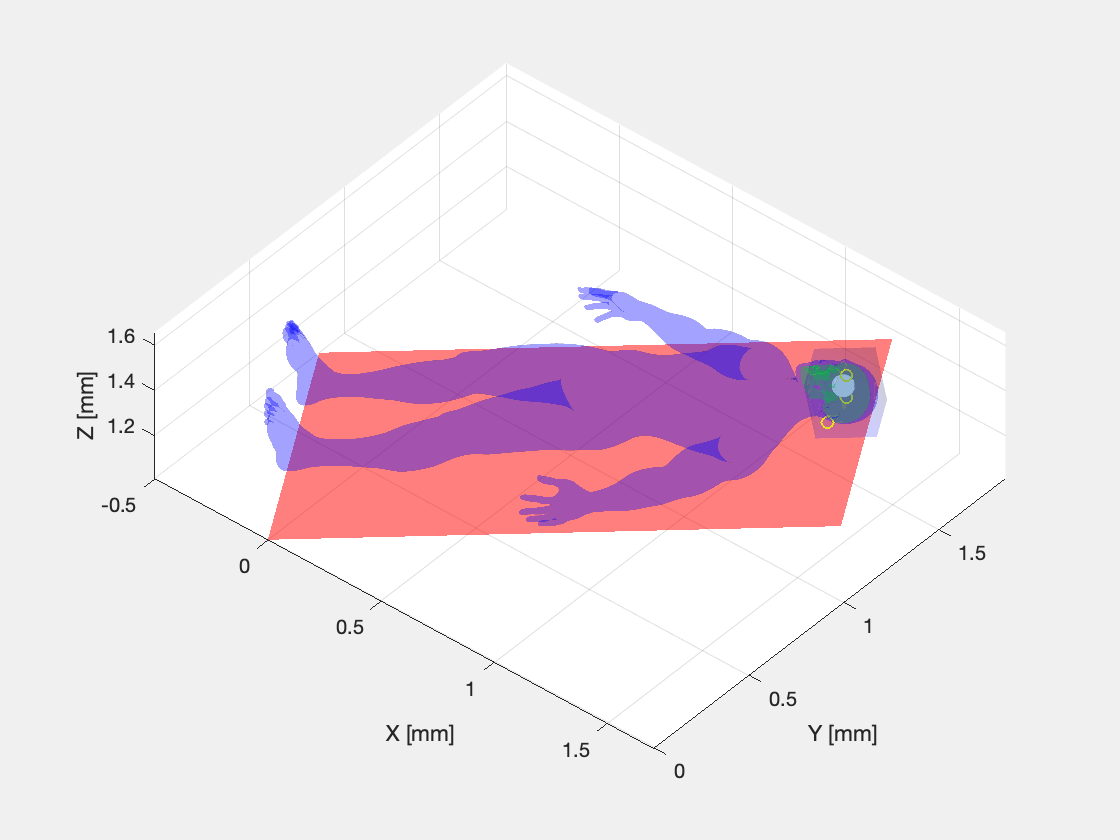

patch_Tumor =   Patch with properties:

    FaceColor: [1 1 1]
    FaceAlpha: 0.8000
    EdgeColor: 'none'
    LineStyle: '-'
        Faces: [800×3 double]
     Vertices: [441×3 double]

  Show all properties



% Dades interessants
max_min_tumor(1,1) = max(v_tumor(:,1)); % max x
max_min_tumor(2,1) = min(v_tumor(:,1)); % min x

max_min_tumor(1,2) = max(v_tumor(:,2)); % max y
max_min_tumor(2,2) = min(v_tumor(:,2)); % min y

max_min_tumor(1,3) = max(v_tumor(:,3)); % max z
max_min_tumor(2,3) = min(v_tumor(:,3)); % min z

centre_Tumor = [(max_min_tumor(1,1)+max_min_tumor(2,1))/2,(max_min_tumor(1,2)+max_min_tumor(2,2))/2,(max_min_tumor(1,3)+max_min_tumor(2,3))/2];

radi = (max_min_tumor(1,3)-max_min_tumor(2,3))/4; % max en z - min en z, diametro tumor


patch_Tumor = FVsPlot(fvc.faces,v_tumor,'white', 0.8)

## *First approach (10%)  *

*Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

### Robot manipulator

Consider  the best position of manipulator to be nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

Use: p560.base & p560.tool to locate the Puma and add the tool.

mdl_puma560
p560.base = T_taula*transl(2.4,0.7,0.15)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, fastRNE             
 - viscous friction; params of 8/95;                              
+---+-----------+-----------+-----------+-----------+-----------+ 
| j |     theta |         d |         a |     alpha |    offset | 
+---+-----------+-----------+-----------+-----------+-----------+ 
|  1|         q1|          0|          0|     1.5708|          0| 
|  2|         q2|          0|     0.4318|          0|          0| 
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0| 
|  4|         q4|     0.4318|          0|     1.5708|          0| 
|  5|         q5|          0|          0|    -1.5708|          0| 
|  6|         q6|          0|          0|          0|          0| 
+---+-----------+-----------+-----------+-----------+-----------+ 
base:    t = (1.67, 1.77, 1.56), RPY/xyz = (30.4, -8.65, 5.04) deg
 


% Marquem limits per a centrar la camara en el que interessa
% el cap
xlim([-2 3])
ylim([-0.7 2.5])
zlim([-0.5 3])
vista_persp = [-260, 20];
workSpace = [1.3 2.3 1.3 2.7 1.2 5];
p560.plot(qr,'zoom',2.5,'workspace', workSpace,'view',vista_persp );
axis equal

Eliminem el crani i la caixa

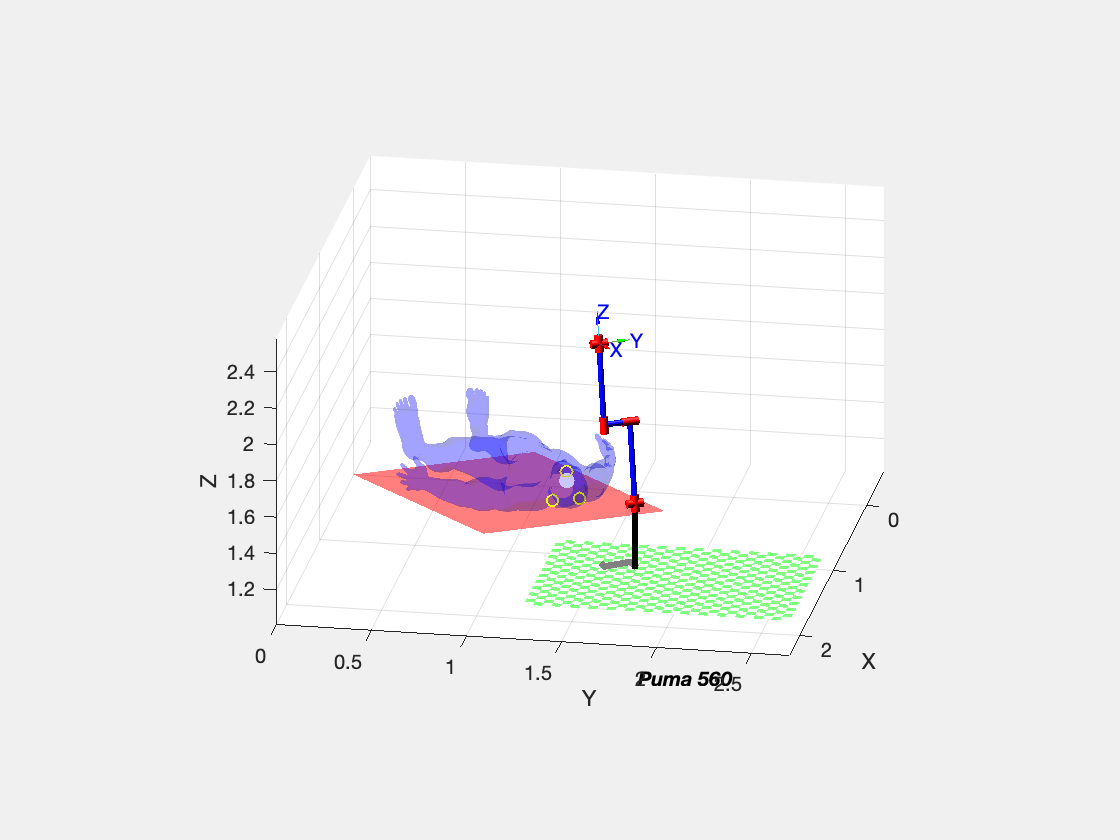

delete(patch_Skull);
delete(patch_Box);

### Reference Frames

Display all necessary reference frame. Use best scale to see it.

- {U} Univers [0 0 0]

- {R} Robot

- {I} Image

- {Tb} Table_body

- {Tt} Table tool

- {EE} End Efector

T_univers = transl(0,0,0)

T_univers =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


%T_robot = T_taula*transl(2.7,0.5,0.15)*trotz(-3*pi/2)
T_robot = T_taula*transl(2.4,0.7,0.15)*trotz(-3*pi/2)

T_robot =    -0.5000   -0.8529   -0.1504    1.6743
    0.8660   -0.4924   -0.0868    1.7750
         0   -0.1736    0.9848    1.5645
         0         0         0    1.0000


%trplot(T_image, 'frame', 'R', 'color', 'black')
%trplot(T_univers, 'frame', 'R', 'color', 'b')
%trplot(T_taula, 'frame', 'R', 'color', 'red')
%trplot(T_box, 'frame', 'R', 'color', 'green')
%trplot(T_robot, 'frame', 'R', 'color', 'yellow')

### Transformations

Get all transformation

%% put your code Here 
T_image_robot = inv(T_image)*T_robot

T_image_robot =     1.0000    0.0000    0.0000    0.3500
         0    0.0000   -1.0000    0.1700
         0    1.0000         0   -0.6000
         0         0         0    1.0000


## Surgery (40%)

### Biopsy

Prepare a script that perform a biopsy. Zoom in the scene and record a video with thwe best view.

Hem de fer:

- Anar a buscar l'eina

- Situar-nos a la part superior del cap

- Entrar a pel tumor

- Sortir

% Dividim moviment en 3
p560.tool = SE3(0,0,0.17);
t = [0:0.05:1]';


T_Eina = SE3(T_robot(1,4),T_robot(2,4)+0.5,T_robot(3,4))*SE3.Ry(pi);
T_Ini = SE3(T_tumor(1,4)+0.15,T_tumor(2,4),T_tumor(3,4))*SE3.Rx(pi/2)*SE3.Ry(-pi/2);
T3_Dins = SE3(T_tumor(1,4),T_tumor(2,4),T_tumor(3,4))*SE3.Rx(pi/2)*SE3.Ry(-pi/2);

vista_persp = [80,40]

vista_persp =     80    40


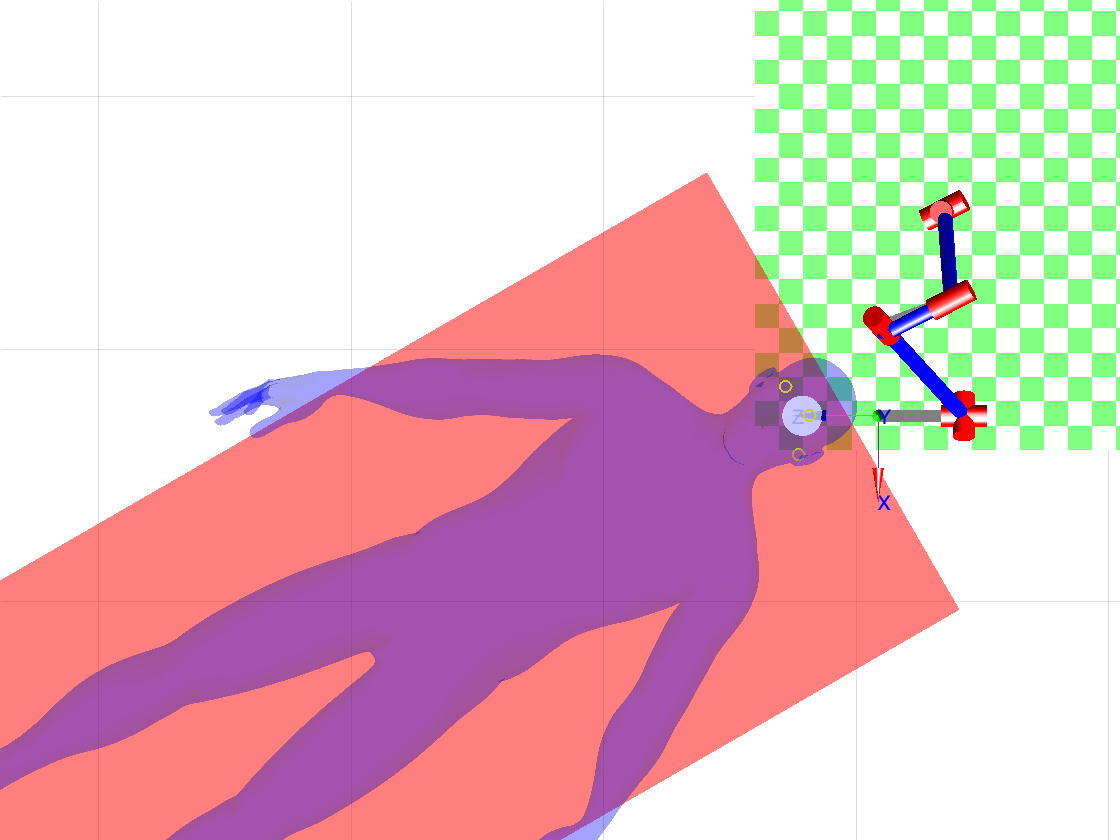

% 1. Anem a buscar a l'eina
q_Eina = p560.ikine6s(T_Eina, 'r');
q_Ini = p560.ikine6s(T_Ini);
q = mtraj(@tpoly, q_Eina, q_Ini, t);
p560.plot(q,'view',vista_persp)  

% 2. Entrem al tumor
q = ctraj(T_Ini, T3_Dins, t);
q = p560.ikine6s(q,'r');
p560.plot(q,'top')

% 3. Sortim del tumor
q = ctraj(T3_Dins, T_Ini, t);
q = p560.ikine6s(q,'r');
p560.plot(q,'top')  

### Trepanation

Prepare a script that perform trepanation.

Hem de fer:

- Agafar eina

- Anar a la part superior del cap

- Fem Forat (1r desplaçem una mica al costat, 2n fem forat cercle)

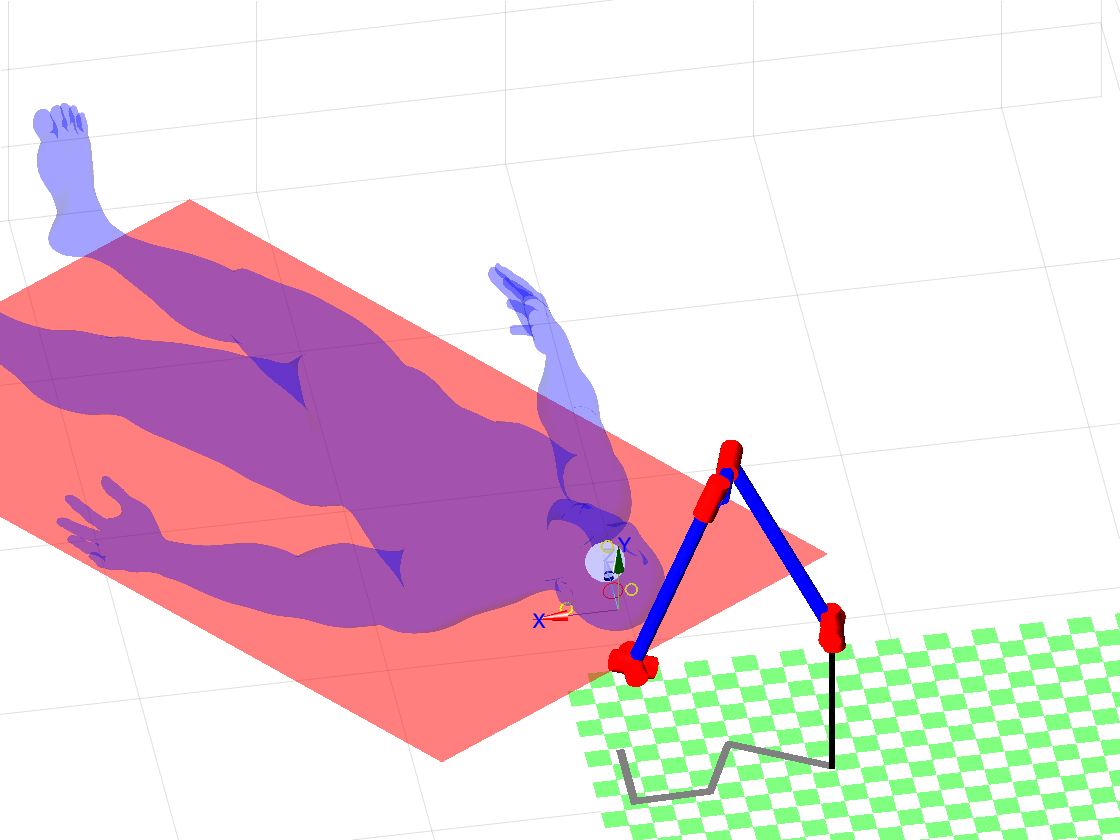

% 0. Anem a buscar l'eina
T_Eina;
T_Ini;
q_Eina;
q_Ini;
q = mtraj(@tpoly, q_Ini, q_Eina, t);
p560.plot(q, 'view', vista_persp)  


% 1. Anem a la posicio inicial
q = mtraj(@tpoly, q_Eina, q_Ini, t);
p560.plot(q, 'view', vista_persp)  
     

% 2. Anem a buscar el forat

% Distancia desde l'agulla fins a tocar el cap
offset_cap = 0.06;

% Calculem el perimetre a tallar
T_Centre = T_Ini*SE3(0,0,offset_cap);

radi_Trepanacio = radi;   % radi o radi/2?
n = 100;

for i=1:n
    Laser_Pose(:,:,i)= T_Centre*SE3.Rz(2*pi*i/n)*SE3.Ry(pi/4)*SE3(radi_Trepanacio, 0,0);
end


% Apuntem al inici del forat
p_ini = Laser_Pose(:,:,1);
T = SE3(p_ini.t(1), p_ini.t(2), p_ini.t(3)) * SE3.Rx(pi/2)*SE3.Ry(-pi/2);
T3_Gir = T * SE3(0,0,-offset_cap);
q_Gir = ctraj(T_Ini, T3_Gir, t);
q_Gir = p560.ikine6s(q_Gir);
p560.plot(q_Gir, 'view', vista_persp);


% 3. Eina a sobre del cap - Anem a T4_Cap
T4_Cap = T_Centre*SE3(radi,0,0);
q_Tornar = ctraj(T3_Gir, T4_Cap, t);
q_Tornar = p560.ikine6s(q_Tornar, 'b');
p560.plot(q_Tornar, 'top');


% 4. Tallem (Cercle) 

% Mostrem la part a tallar
plotCircle3D([T_Centre.t(1),T_Centre.t(2),T_Centre.t(3)],[1,0,0],radi_Trepanacio);

% Trepanem 
q = p560.ikine6s(Laser_Pose, 'run'); 
p560.plot(q, 'view', vista_persp)


% 5. Tornem a la posicio inicial
q = ctraj(Laser_Pose(:,:,n), T_Ini, t);
q = p560.ikine6s(q);
p560.plot(q, 'view', vista_persp);

### Tumor burning

Prepare a script that perform tumor burning with the laser.

% 0. Anem a buscar l'eina
T_Eina;
T_Ini;
q_Eina;
q_Ini;
q = mtraj(@tpoly, q_Ini, q_Eina, t);
p560.plot(q, 'view', vista_persp)  


% 1. Anem a la posicio inicial
q = mtraj(@tpoly, q_Eina, q_Ini, t);
p560.plot(q, 'view', vista_persp)   


% 2. Eina a sobre del cap
T_Centre;
q = ctraj(T_Ini, T_Centre, t);
q = p560.ikine6s(q, 'b');
p560.plot(q, 'top');



% 3: Entrem a cremar el tumor
% L'idea es cremar desde 4 angles diferents. Cremarem abaix, esquerra,
% dreta i abaix del tumor.
% Cada 4 iteracions anirem disminuint el angle d'incidencia
max_min_tumor; % 2-min
    
% Repetim 3 cops els 4 angles
for rad=1:3
    %Cremem en 4 direccions. Abaix, Esquerra, Dreta i Adalt.
    for i=1:4
        %Ens encarem amb el angle que toca 
        if i == 1
            T1 = T_Centre*SE3.Rx(pi/(10*rad));
        end
        if i == 2
            T1 = T_Centre*SE3.Ry(pi/(10*rad));
        end
        if i == 3
            T1 = T_Centre*SE3.Rx(-pi/(10*rad));
        end
        if i == 4
            T1 = T_Centre*SE3.Ry(-pi/(10*rad)); 
        end
        q = ctraj(T_Centre, T1, 20);
        q = p560.ikine6s(q);
        p560.plot(q, 'view', vista_persp);
        
        %Entrem al cap rectes
        T2 = T1*SE3(0,0,radi*4); % Anem a parar al centre del Tumor (en profunditat)
        q = ctraj(T1, T2, 20);
        q = p560.ikine6s(q);
        p560.plot(q, 'view', vista_persp);
        
        %Sortim del cap
        q = ctraj(T2, T1, 20);
        q = p560.ikine6s(q);
        p560.plot(q, 'view', vista_persp);
        
        %Tornem a la posicio inicial
        q = ctraj(T1, T_Centre, 20);
        q = p560.ikine6s(q);
        p560.plot(q, 'view', vista_persp);
    end
end



%Tornem a la posicio inicial
q = ctraj(T_Centre, T_Ini, t);
q = p560.ikine6s(q);
p560.plot(q, 'view', vista_persp);

function T_b_a=FVsPlot(F,V,color, alp)
T_b_a = patch('Faces',F,'Vertices',V,'FaceColor',color, ...
         'FaceAlpha',alp,...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('dull');

grid on
xlabel 'X [mm]'
ylabel 'Y [mm]'
zlabel 'Z [mm]'
axis equal
end